# Pain only stimulus intensity maps

# Linear effects of stimlus intensity (low < med < high)

Pain only :: load dataset

clear all;
close all;

contrast_of_interest = 'P_simple_STIM_cue_high_gt_low'

contrast_of_interest = 'P_simple_STIM_cue_high_gt_low'

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_highlowcue_rampplateau/1stlevel';
contrast_name = {
    'P_VC_STIM_cue_high_gt_low', 'V_PC_STIM_cue_high_gt_low', 'C_PV_STIM_cue_high_gt_low',...% contratss
    'P_VC_STIM_stimlin_high_gt_low', 'V_PC_STIM_stimlin_high_gt_low', 'C_PV_STIM_stimlin_high_gt_low',...
    'P_VC_STIM_stimquad_med_gt_other', 'V_PC_STIM_stimquad_med_gt_other', 'C_PV_STIM_stimquad_med_gt_other',...
    'P_VC_STIM_cue_int_stimlin','V_PC_STIM_cue_int_stimlin', 'C_PV_STIM_cue_int_stimlin',...
    'P_VC_STIM_cue_int_stimquad','V_PC_STIM_cue_int_stimquad','C_PV_STIM_cue_int_stimquad',...
    'motor',... %motor
    'P_simple_STIM_cue_high_gt_low','V_simple_STIM_cue_high_gt_low', 'C_simple_STIM_cue_high_gt_low',... % dummay contrasts
    'P_simple_STIM_stimlin_high_gt_low',  'V_simple_STIM_stimlin_high_gt_low', 'C_simple_STIM_stimlin_high_gt_low',...
    'P_simple_STIM_stimquad_med_gt_other','V_simple_STIM_stimquad_med_gt_other', 'C_simple_STIM_stimquad_med_gt_other',...
    'P_simple_STIM_cue_int_stimlin',      'V_simple_STIM_cue_int_stimlin', 'C_simple_STIM_cue_int_stimlin',...
    'P_simple_STIM_cue_int_stimquad',     'V_simple_STIM_cue_int_stimquad','C_simple_STIM_cue_int_stimquad',...
    'P_simple_STIM_highcue_highstim',     'P_simple_STIM_highcue_medstim', 'P_simple_STIM_highcue_lowstim',... % pain events
    'P_simple_STIM_lowcue_highstim',      'P_simple_STIM_lowcue_medstim', 'P_simple_STIM_lowcue_lowstim',...
    'V_simple_STIM_highcue_highstim',     'V_simple_STIM_highcue_medstim', 'V_simple_STIM_highcue_lowstim',... % vicarious events
    'V_simple_STIM_lowcue_highstim',      'V_simple_STIM_lowcue_medstim', 'V_simple_STIM_lowcue_lowstim',...
    'C_simple_STIM_highcue_highstim',    'C_simple_STIM_highcue_medstim', 'C_simple_STIM_highcue_lowstim',... % cognitive events
    'C_simple_STIM_lowcue_highstim',    'C_simple_STIM_lowcue_medstim', 'C_simple_STIM_lowcue_lowstim',...
    'P_VC_CUE_cue_high_gt_low','V_PC_CUE_cue_high_gt_low','C_PV_CUE_cue_high_gt_low',...% cue epoch contrasts
    'P_simple_CUE_cue_high_gt_low','V_simple_CUE_STIM_cue_high_gt_low','C_simple_CUE_cue_high_gt_low',...% cue epoch dummy
    'G_simple_CUE_cue_high_gt_low',...
    'P_VC_STIM', 'V_PC_STIM', 'C_PV_STIM'
};
index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 28753056 bytes
Loading image number:    72
Elapsed time is 24.385037 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6899522  Bit rate: 22.72 bits


`Pain only :: check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:18:09 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


asdf

Pain only :: Plot diagnostics, before l2norm

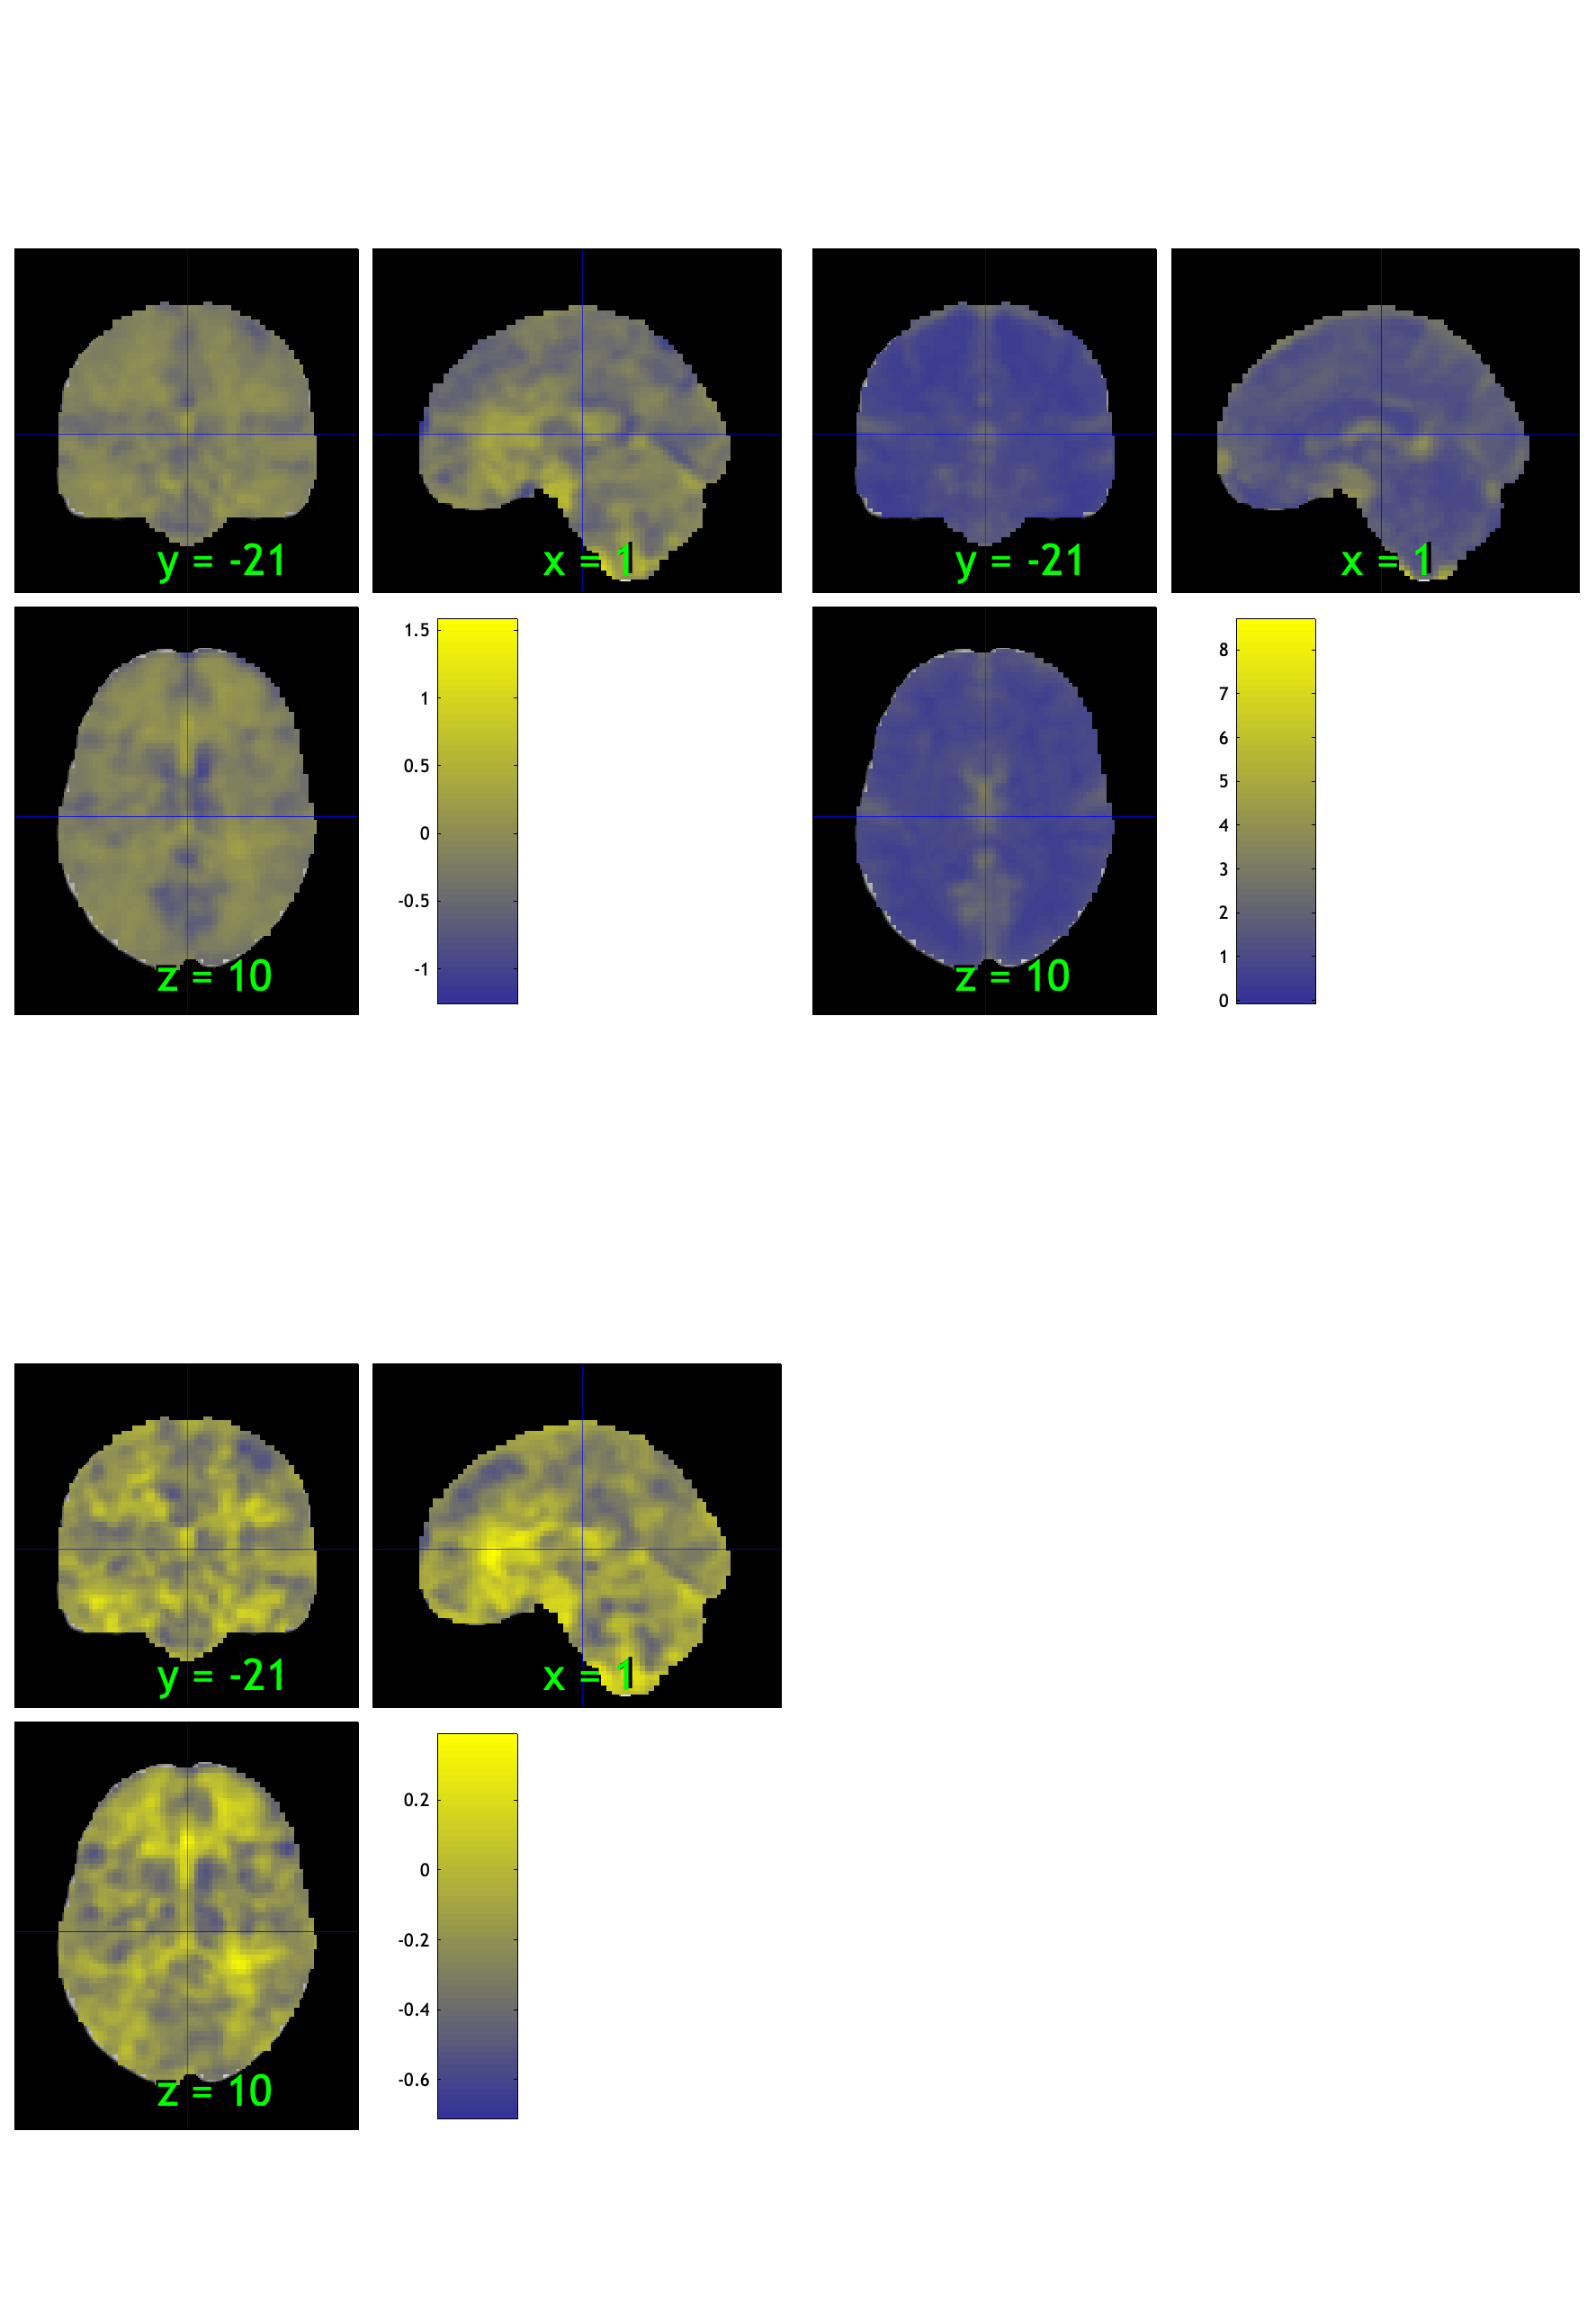

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 29.17%
Expected 3.60 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 29 44 
Uncorrected: 7 images		Cases 7 26 29 37 44 65 70 

Retained 7 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 56.94%
Expected 3.60 outside 95% ellipsoid, found   1

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 1 images		Cases 58 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                               

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:18:46 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

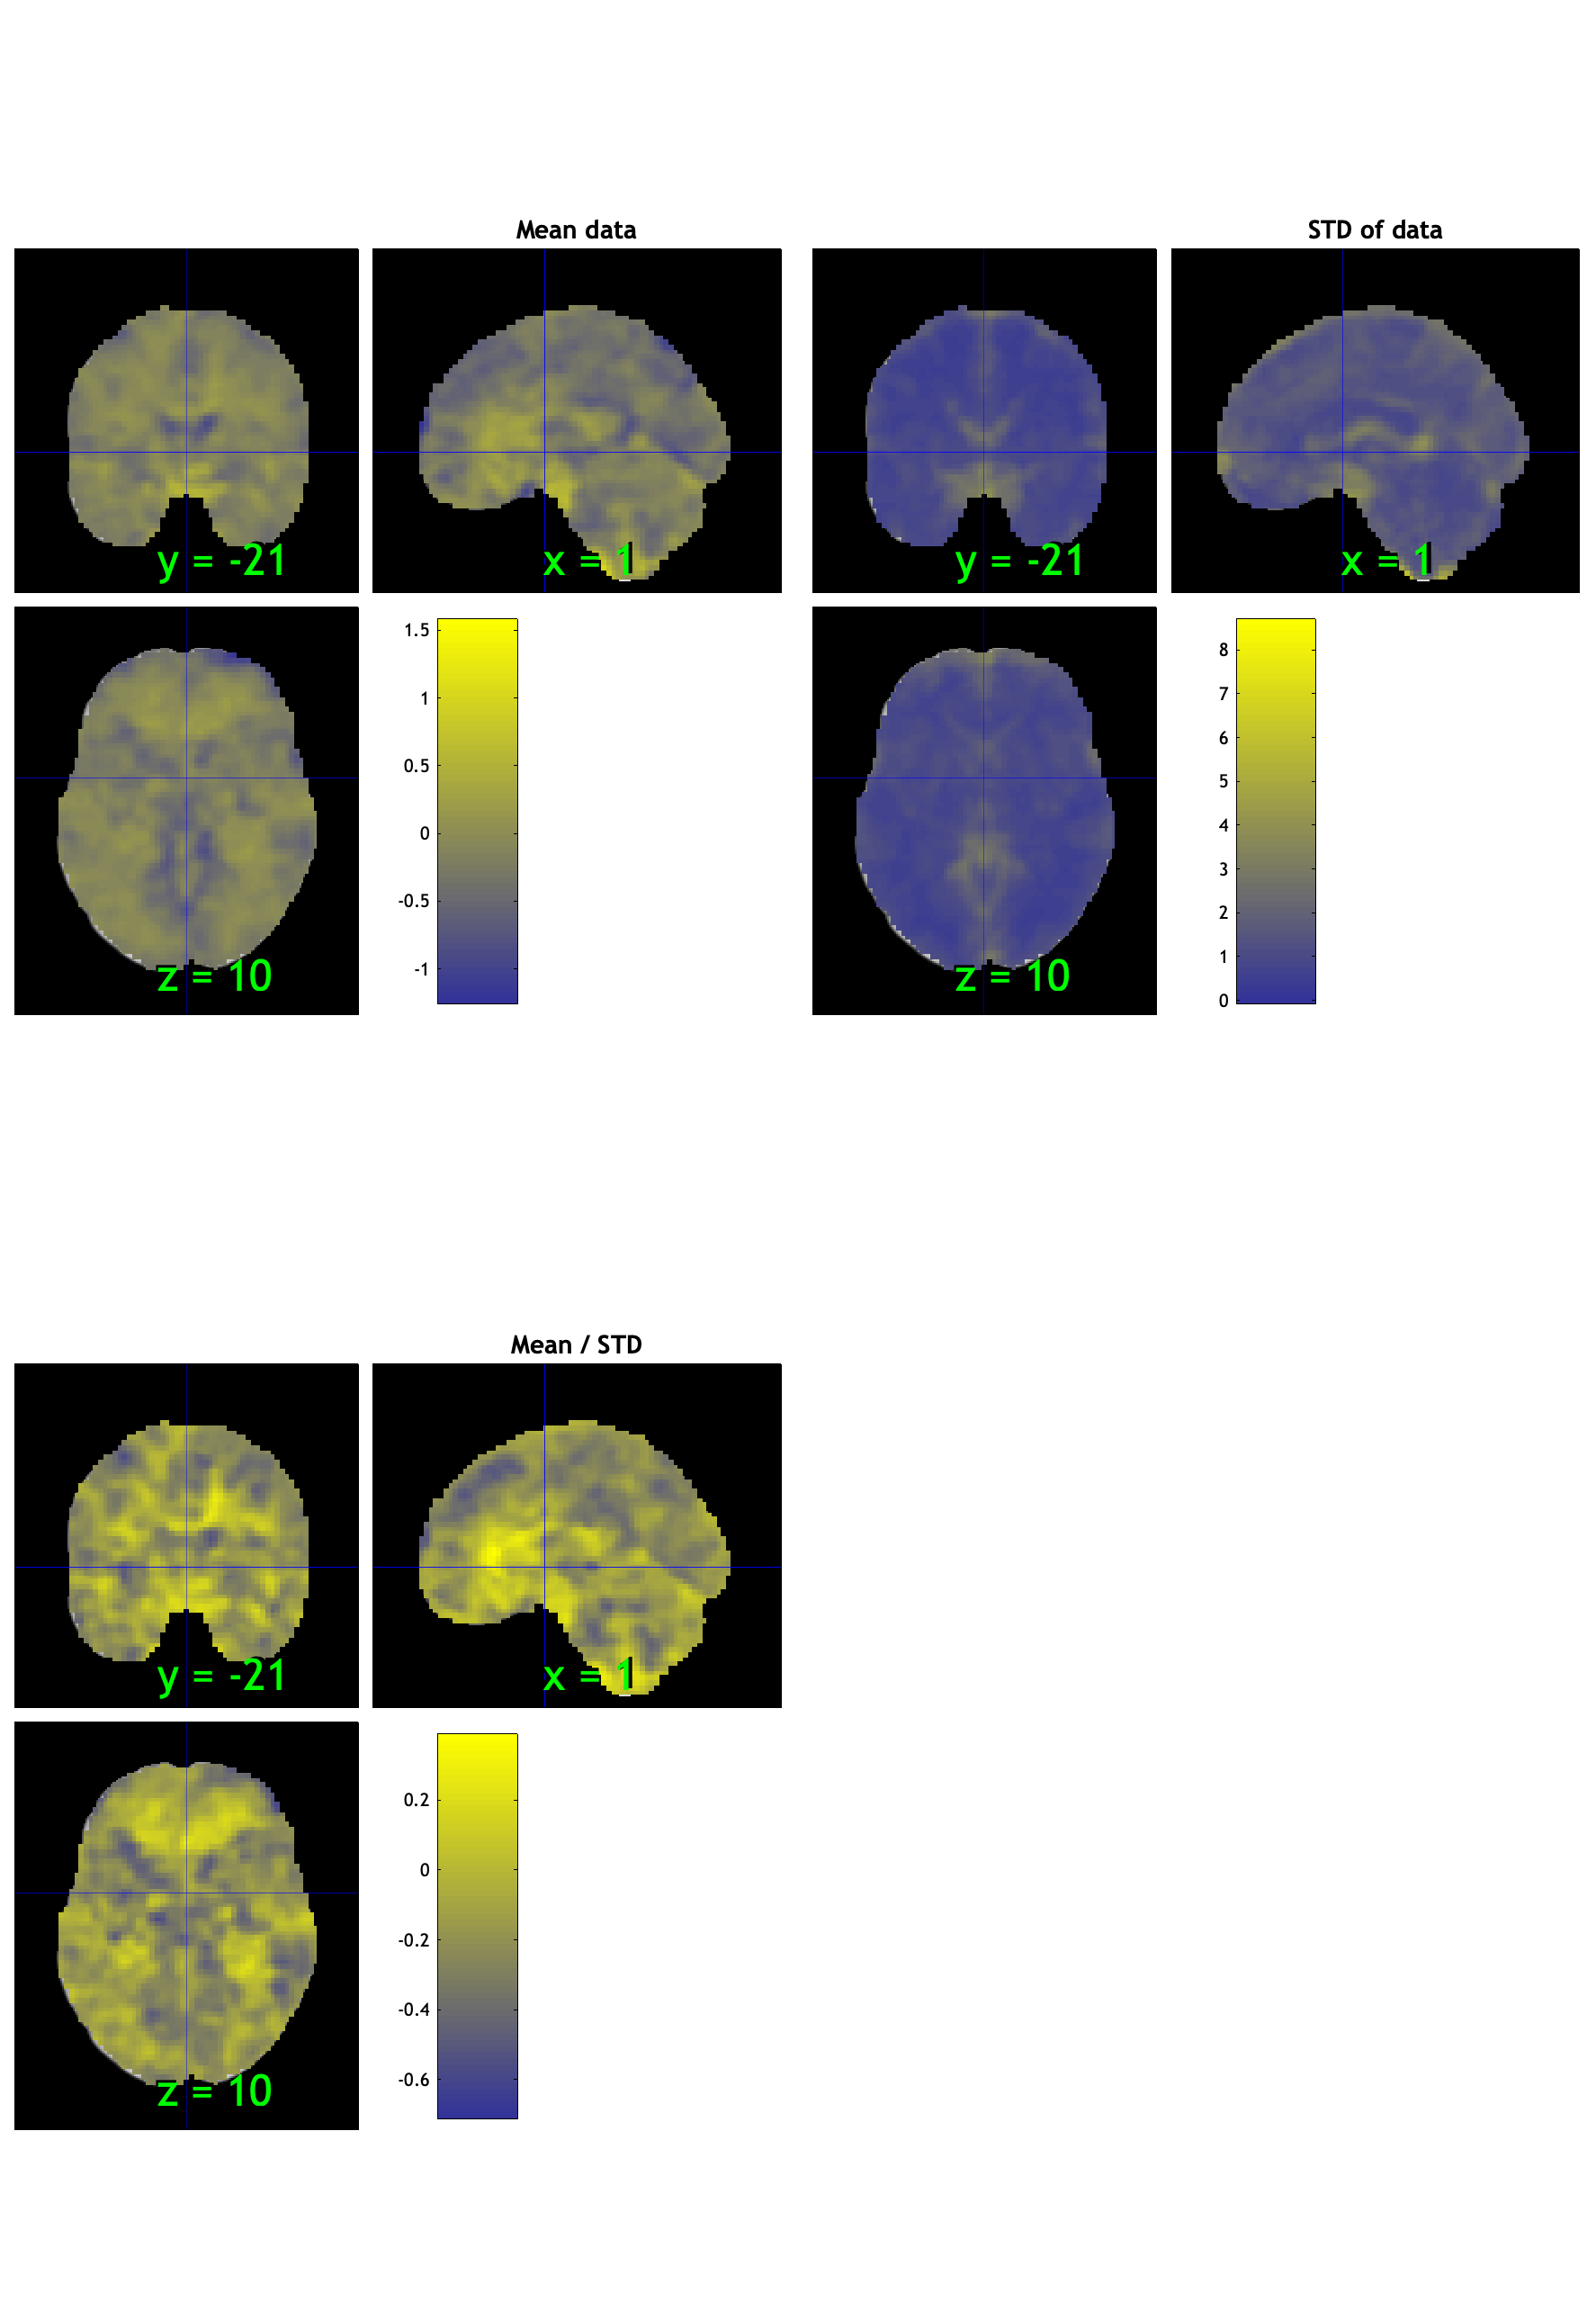

drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

Remove outlier

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 72


%for s = 1:length(wh_outlier_corr)
%disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 2 participants, size is now 70


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0074"    "participants that are outliers:... sub-0093"



disp(n);

`imgs2 = con.rescale(``'l2norm_images');`

# `regression`

### `Load behavioral cue effects. prepare covariates and identify intersection subjects with fMRI data`

beh_cueeffect = readtable('/Users/h/Documents/projects_local/cue_expectancy/analysis/mixedeffect/dataframes/beh_cueeffect_rawoutcome.csv')

beh_cueeffect = 342×26 table
        sub             task         raw_outcome_cue    raw_outcome_cue_sd    z_outcome_cue    z_outcome_cue_sd    raw_expect_cue    raw_expect_cue_sd    z_expect_cue    z_expect_cue_sd    raw_outcome_stim    raw_outcome_stim_sd    z_outcome_stim    z_outcome_stim_sd    raw_expect_stim    raw_expect_stim_sd    z_expect_stim    z_expect_stim_sd    cuestim_raw_outcome    cuestim_raw_outcome_reg    cuestim_z_outcome    cuestim_z_outcome_reg    cuestim_raw_expect    cuestim_raw_expect_reg    cuestim_z_expect    cuestim_z_expect_reg

pain_task = find(strcmp(beh_cueeffect.task, 'pain'));

pain_cueeffect = beh_cueeffect(pain_task, :);

% extract subject ids from contrast fMRI data object and intersect with
% behavioral data
nRows = size(con_data_obj.image_names, 1);
sub_ids = cell(nRows, 1);

for i = 1:nRows
    sub_ids{i} = con_data_obj.image_names(i, 1:8);
end

sub_ids_table = table(sub_ids, 'VariableNames', {'sub'});
common_subs = intersect(sub_ids_table.sub, pain_cueeffect.sub)

common_subs = 71×1 cell array
    {'sub-0014'}
    {'sub-0026'}
    {'sub-0028'}
    {'sub-0029'}
    {'sub-0030'}
    {'sub-0031'}
    {'sub-0033'}
    {'sub-0035'}
    {'sub-0039'}
    {'sub-0040'}
    {'sub-0041'}
    {'sub-0043'}
    {'sub-0044'}
    {'sub-0047'}
    {'sub-0050'}
    {'sub-0051'}
    {'sub-0053'}
    {'sub-0055'}
    {'sub-0058'}
    {'sub-0060'}
    {'sub-0061'}
    {'sub-0062'}
    {'sub-0064'}
    {'sub-0066'}
    {'sub-0068'}
    {'sub-0069'}
    {'sub-0070'}
    {'sub-0073'}
    {'sub-0074'}
    {'sub-0076'}


% Ensure beh_cueeffect.sub is a cell array for comparison
if ~iscell(pain_cueeffect.sub)
    pain_cueeffect.sub = cellstr(pain_cueeffect.sub);
end

rows_to_keep = ismember(pain_cueeffect.sub, common_subs);
filtered_pain_cueeffect = pain_cueeffect(rows_to_keep, :);

% regenerate contrast filenames based on intersecting subject ids
% Initialize an empty cell array for the file paths
filteredcon_files = cell(length(common_subs), 1);

% Loop through each subject ID and construct the file path
for i = 1:length(common_subs)
    filteredcon_files{i} = fullfile(mount_dir, common_subs{i}, [common_subs{i}, '_con_0020.nii']);
end


# covariates "Cue effects (Raw outcome)"

Adding Raw covariates to fmri data obj

filtered_con_obj = fmri_data(filteredcon_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 28353708 bytes
Loading image number:    71
Elapsed time is 22.824424 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6767782  Bit rate: 22.69 bits


filtered_con_obj.X = filtered_pain_cueeffect.raw_outcome_cue;
out = regress(filtered_con_obj)

Analysis: 
----------------------------------
Design matrix warnings:
----------------------------------
No intercept detected, adding intercept to last column of design matrix                                                     
Warning!!!  Some observations have high leverage values relative to others, regression may be unstable. abs(z(leverage)) > 3
Warning!!!  Too few variable names entered, less than size(X, 2). Names may be inaccurate.                                  
 
______________________________________________________
Running regression: 99837 voxels. Design:  71 obs,   2 regressors, intercept is last

Predicting exogenous variable(s) in dat.X using brain data as predictors, mass univariate
Running in OLS Mode
Model run in 0 minutes and 0.16 seconds

Creating beta and t images, thresholding t images
___________________________________________________

out = struct with fields:
             analysis_name: ''
          input_parameters: [1×1 struct]
      input_image_metadata: [1×1 struct]
                         X: [71×2 double]
            variable_names: {2×1 cell}
                         C: []
            contrast_names: {}
    contrast_summary_table: [0×0 table]
               diagnostics: [1×1 struct]
                  warnings: {1×4 cell}
                         b: [1×1 statistic_image]
                         t: [1×1 statistic_image]
                        df: [1×1 fmri_data]
                     sigma: [1×1 fmri_data]



m = mean(filtered_con_obj);
m.dat = sum(~isnan(filtered_con_obj.dat) & filtered_con_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:19:25 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


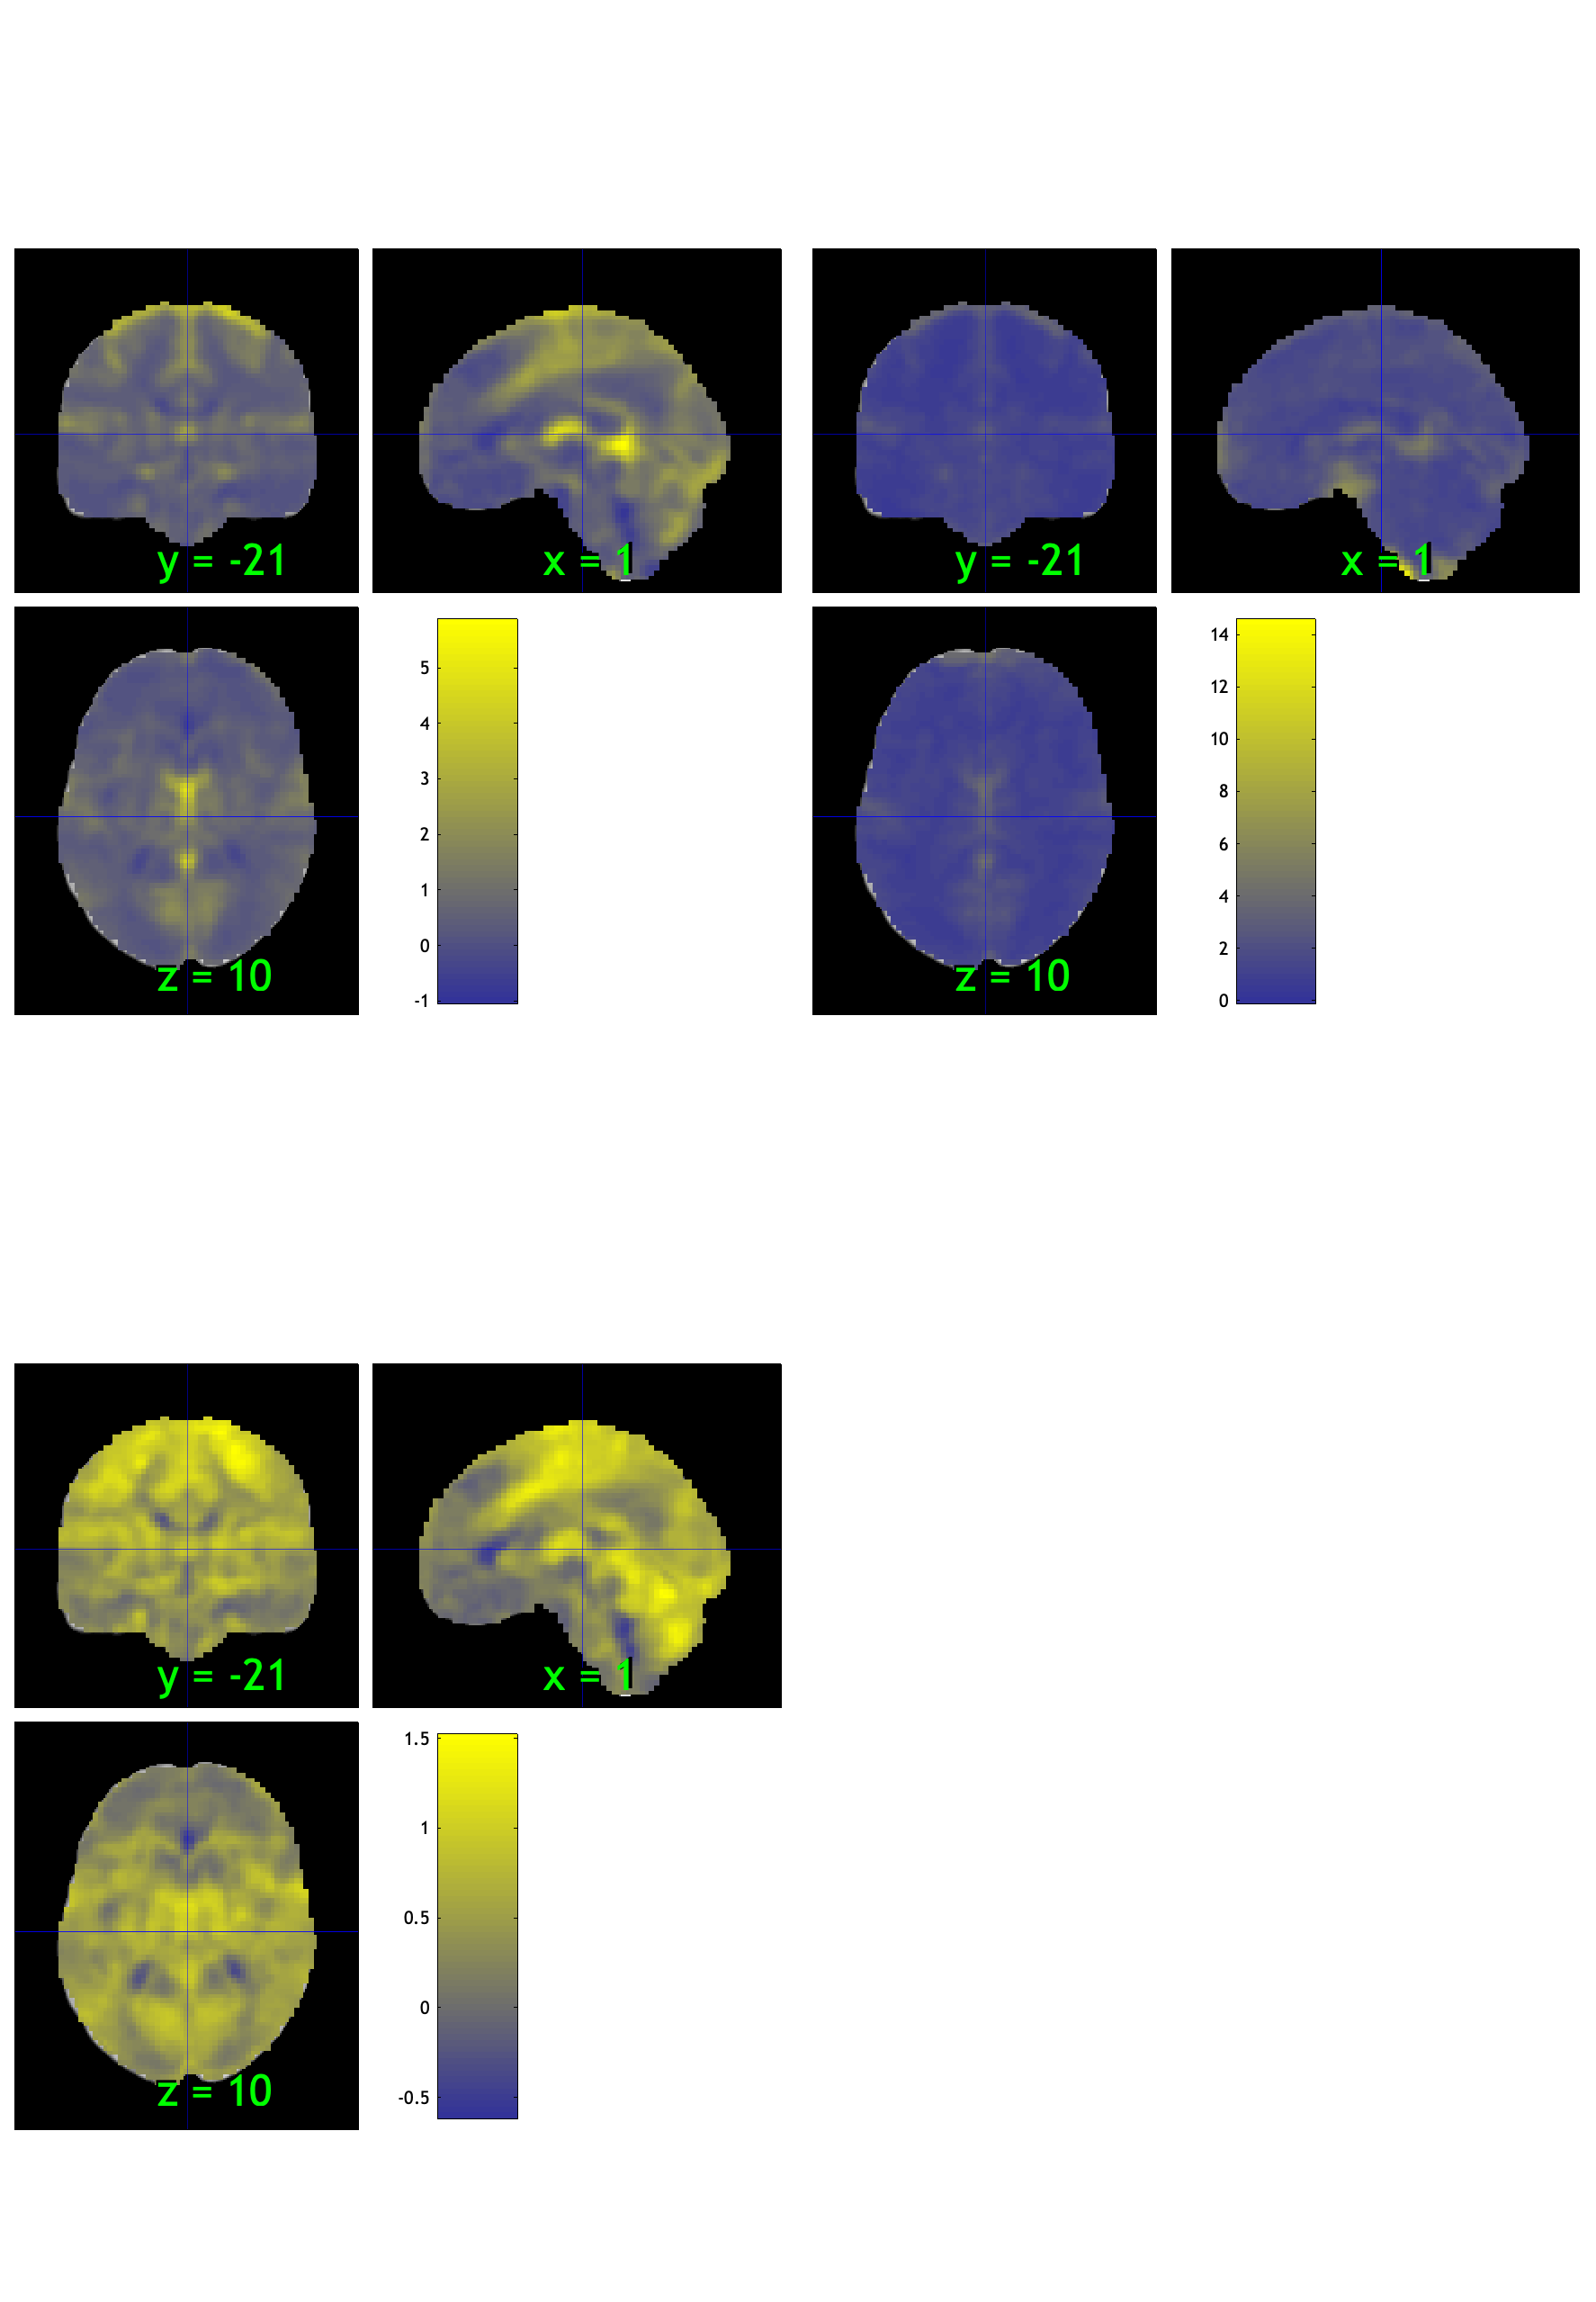

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 21.13%
Expected 3.55 outside 95% ellipsoid, found   9

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 5 images		Cases 16 29 37 44 69 
Uncorrected: 9 images		Cases 12 16 29 34 37 43 44 48 69 

Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 50.70%
Expected 3.55 outside 95% ellipsoid, found   3

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 3 images		Cases 12 20 33 

Mahalanobis (cov and corr, q<0.05 corrected):
  5 images 
                               Outlier_count    Percentage
             

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:20:03 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

wh_outlier_uncorr = 71×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


wh_outlier_corr = 71×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0



% Pain > baseline :: Plot diagnostics, before l2norm
drawnow; snapnow
[wh_outlier_uncorr, wh_outlier_corr] = plot(filtered_con_obj)

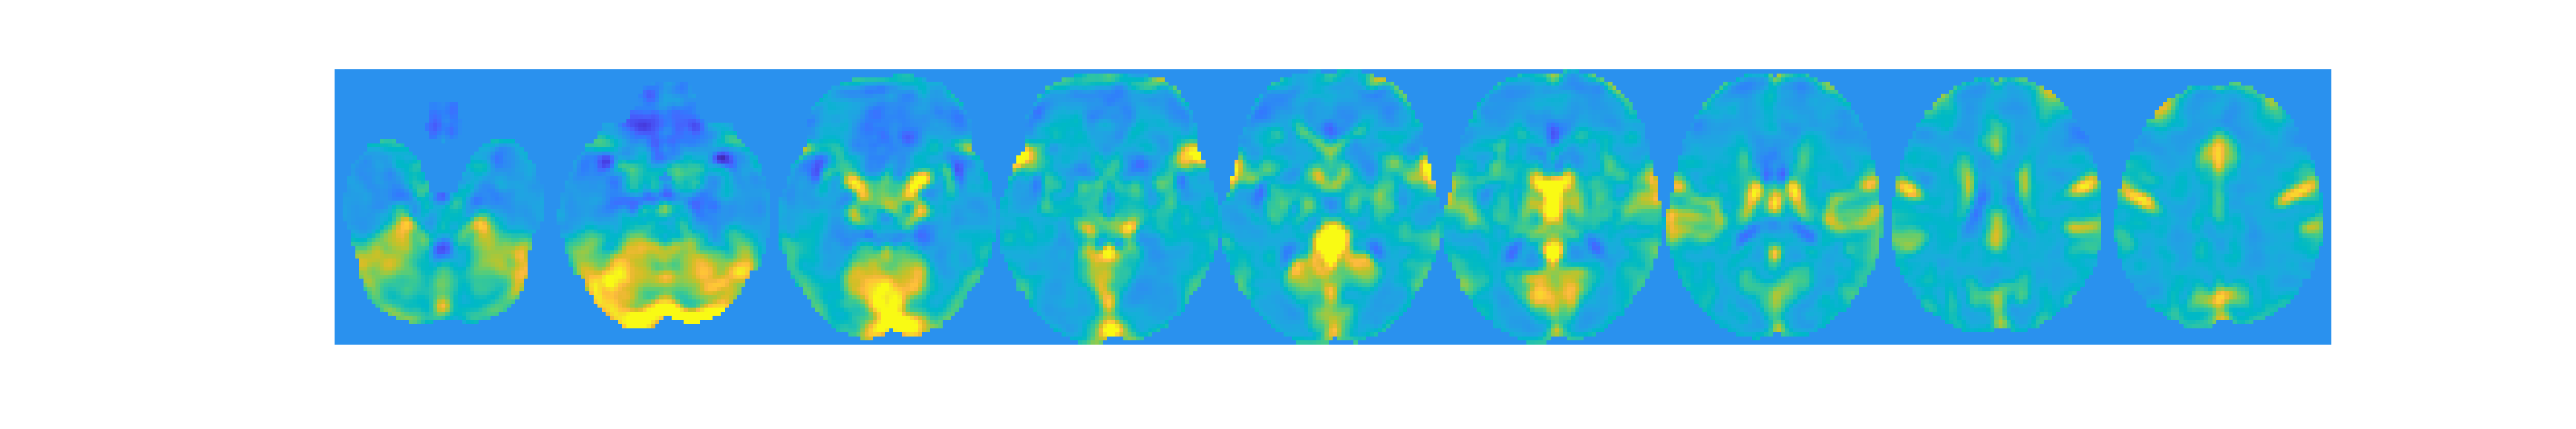

set(gcf,'Visible','on')

figure ('Visible', 'on');
drawnow, snapnow;
con = filtered_con_obj;
disp(strcat("current length is ", num2str(size(filtered_con_obj.dat,2))))

current length is 71


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = filtered_con_obj.dat(:,~wh_outlier_corr);
con.image_names = filtered_con_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: [71×1 double]
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×66 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [66×21 char]
              fullpath: [71×136 char]
           files_exist: [71×1 logical]
            

con.fullpath = filtered_con_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: [71×1 double]
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×66 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [66×21 char]
              fullpath: [66×136 char]
           files_exist: [71×1 logical]
            

con.files_exist = filtered_con_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: [71×1 double]
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×66 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [66×21 char]
              fullpath: [66×136 char]
           files_exist: [66×1 logical]
            

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 5 participants, size is now 66



% plot diagnostics after l2norm
imgs2 = con.rescale('l2norm_images');

%
t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


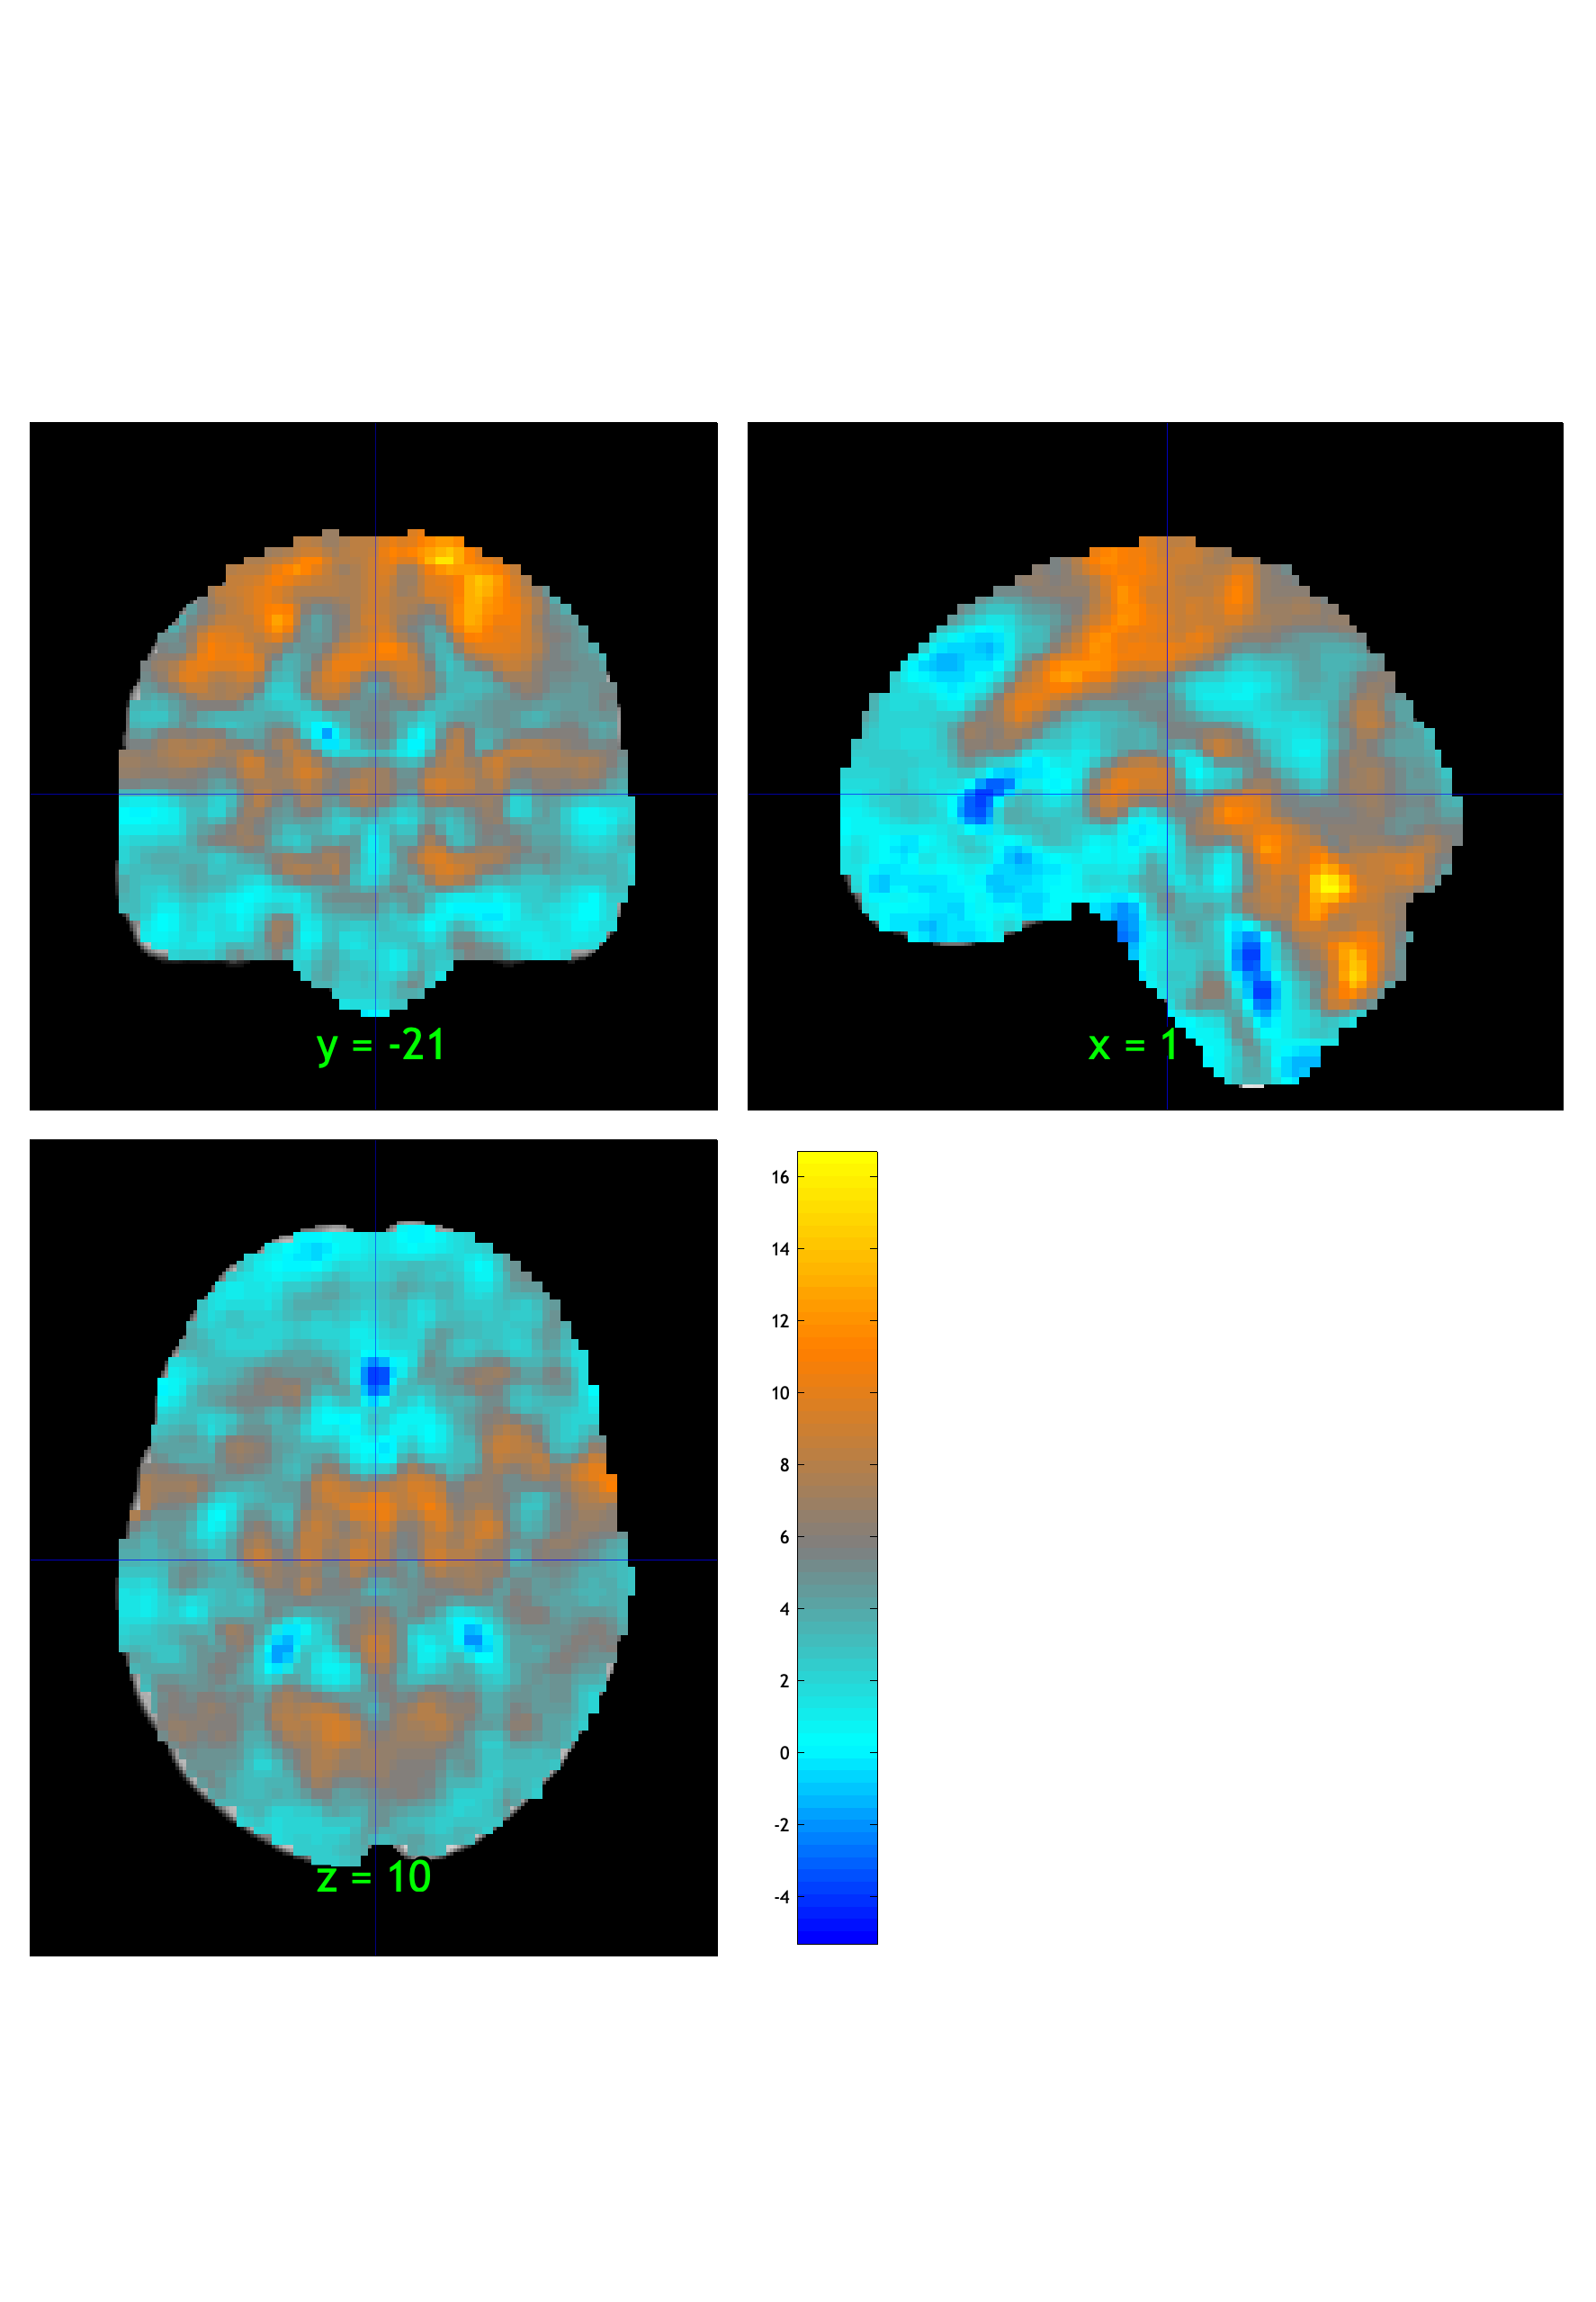

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:20:07 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t05 = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.037811

Image   1
 36 contig. clusters, sizes   1 to 75189
Positive effect: 75174 voxels, min p-value: 0.00000000
Negative effect: 324 voxels, min p-value: 0.00000286


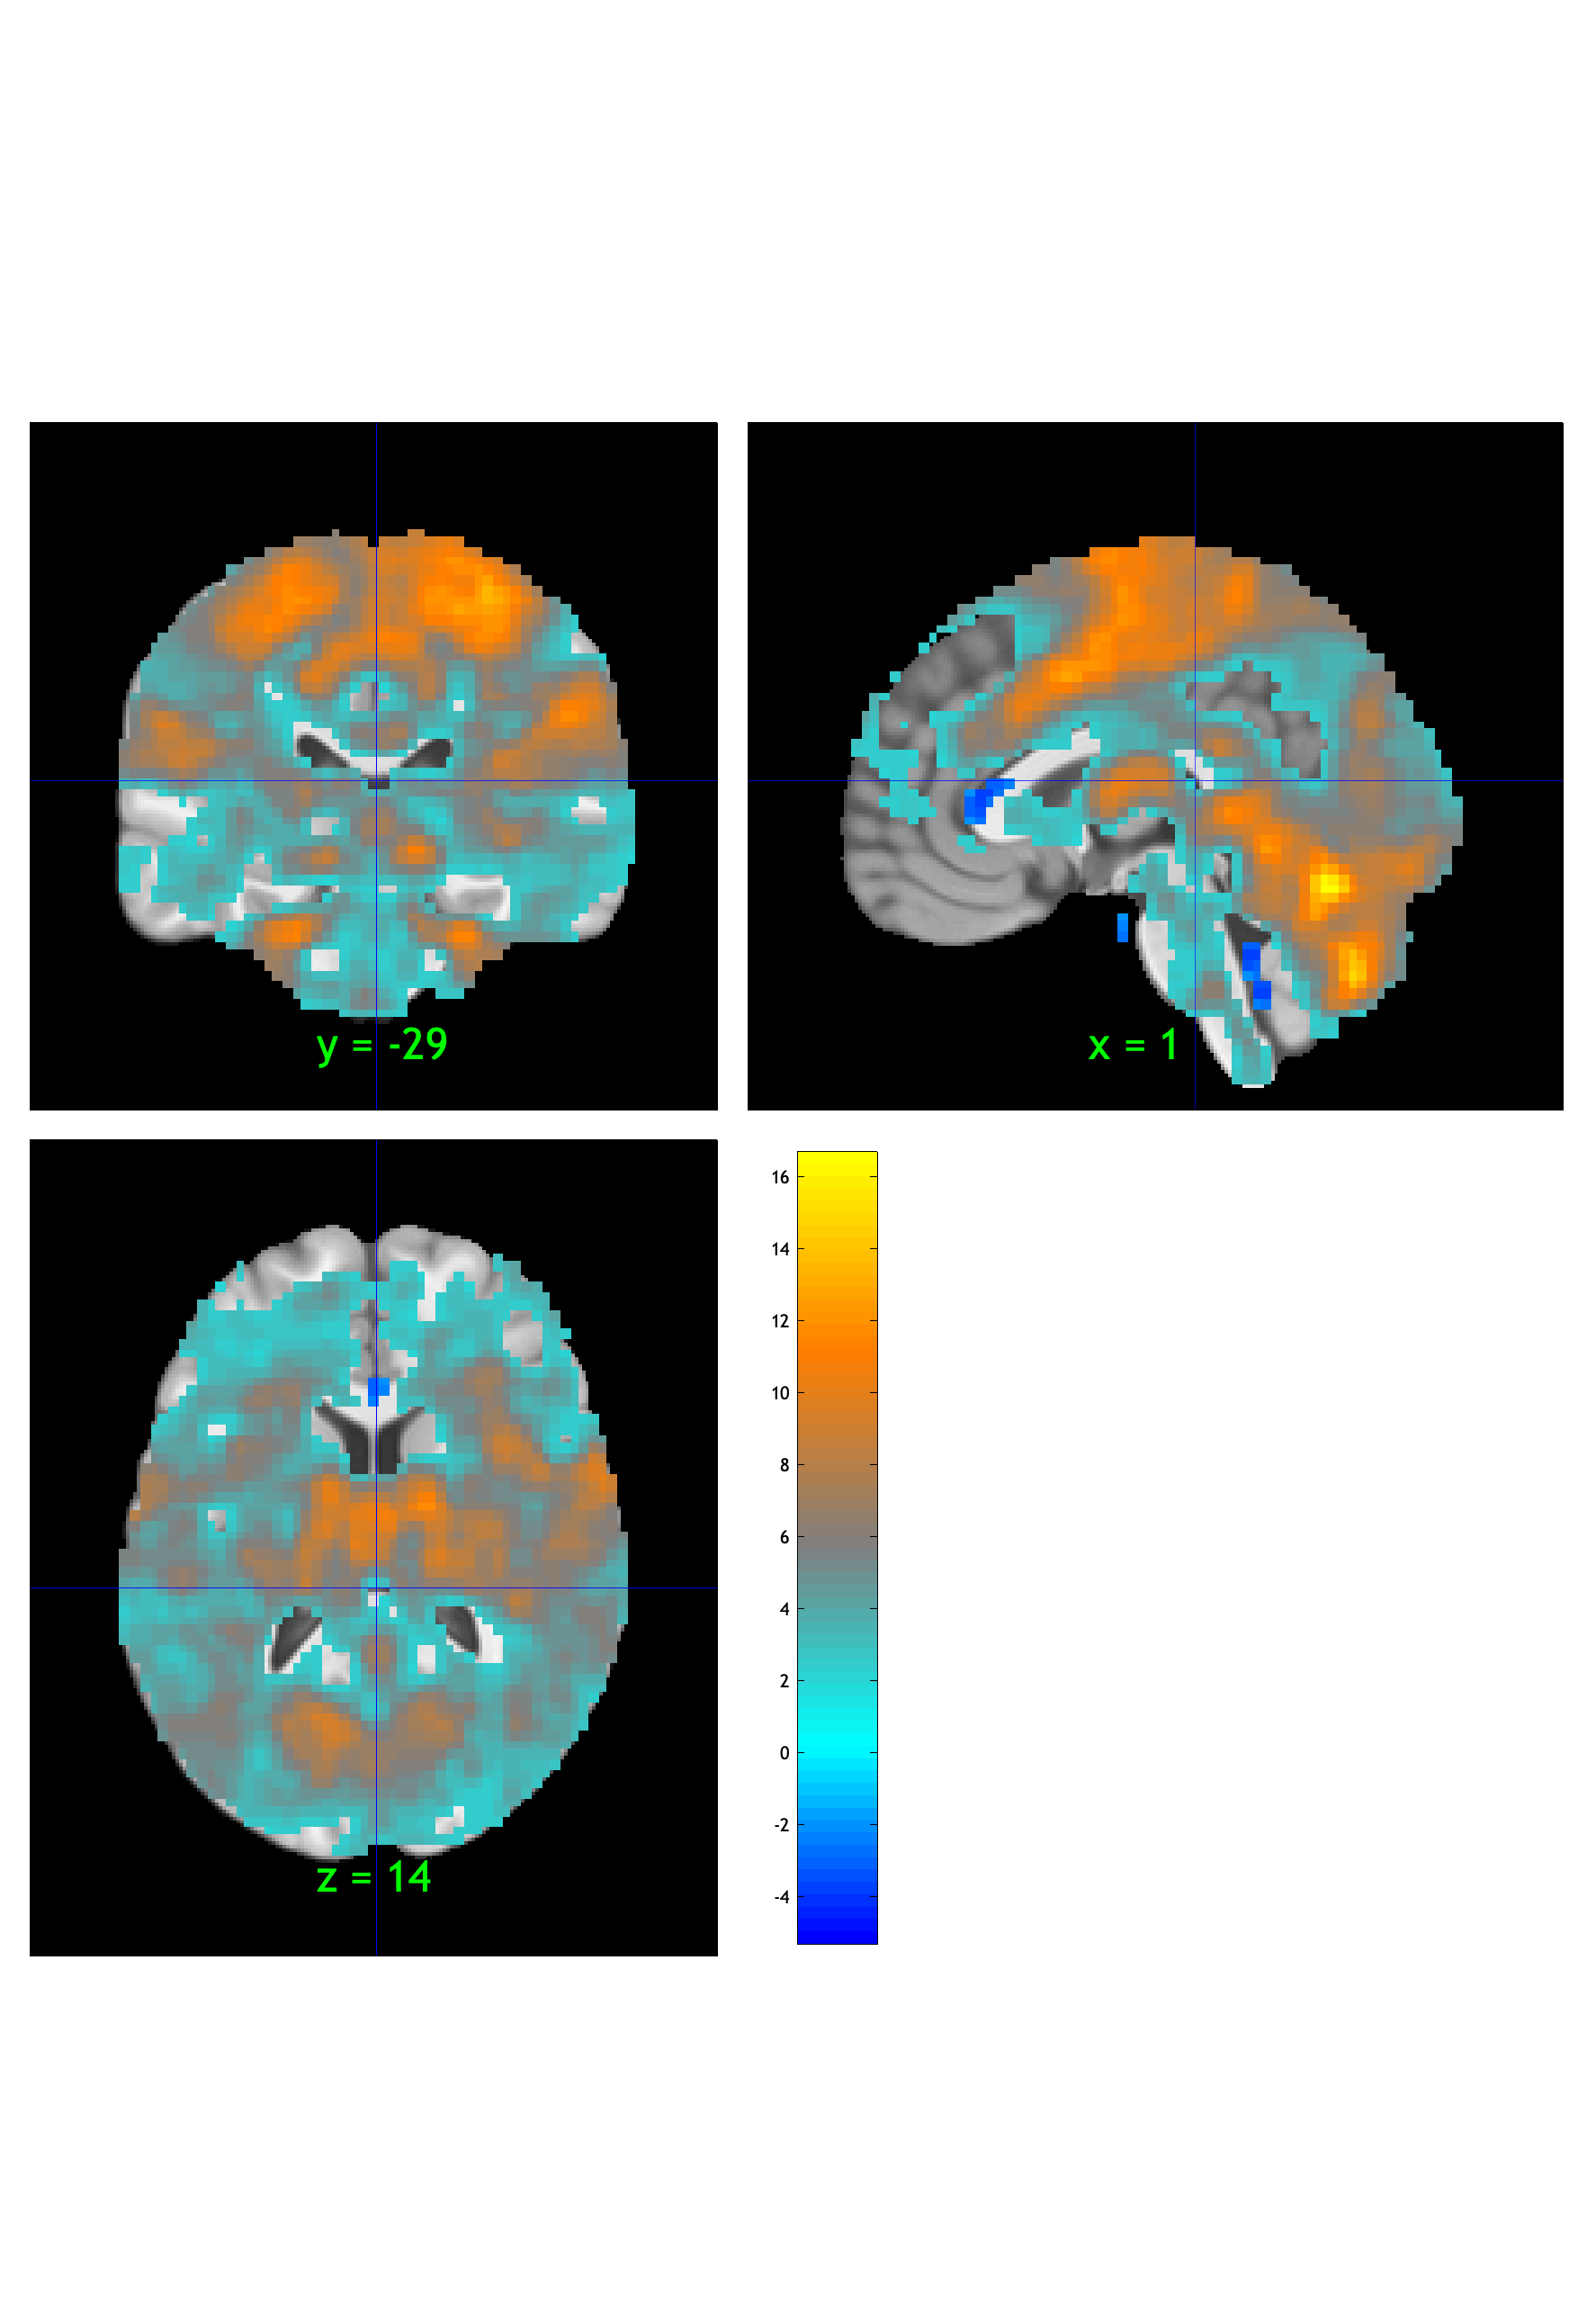

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:20:08 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t05);

drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig

fdr_t05 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 0.0378
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 65
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


%write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

fdr_t001 = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000527

Image   1
 33 contig. clusters, sizes   1 to 52003
Positive effect: 52573 voxels, min p-value: 0.00000000
Negative effect:  35 voxels, min p-value: 0.00000286


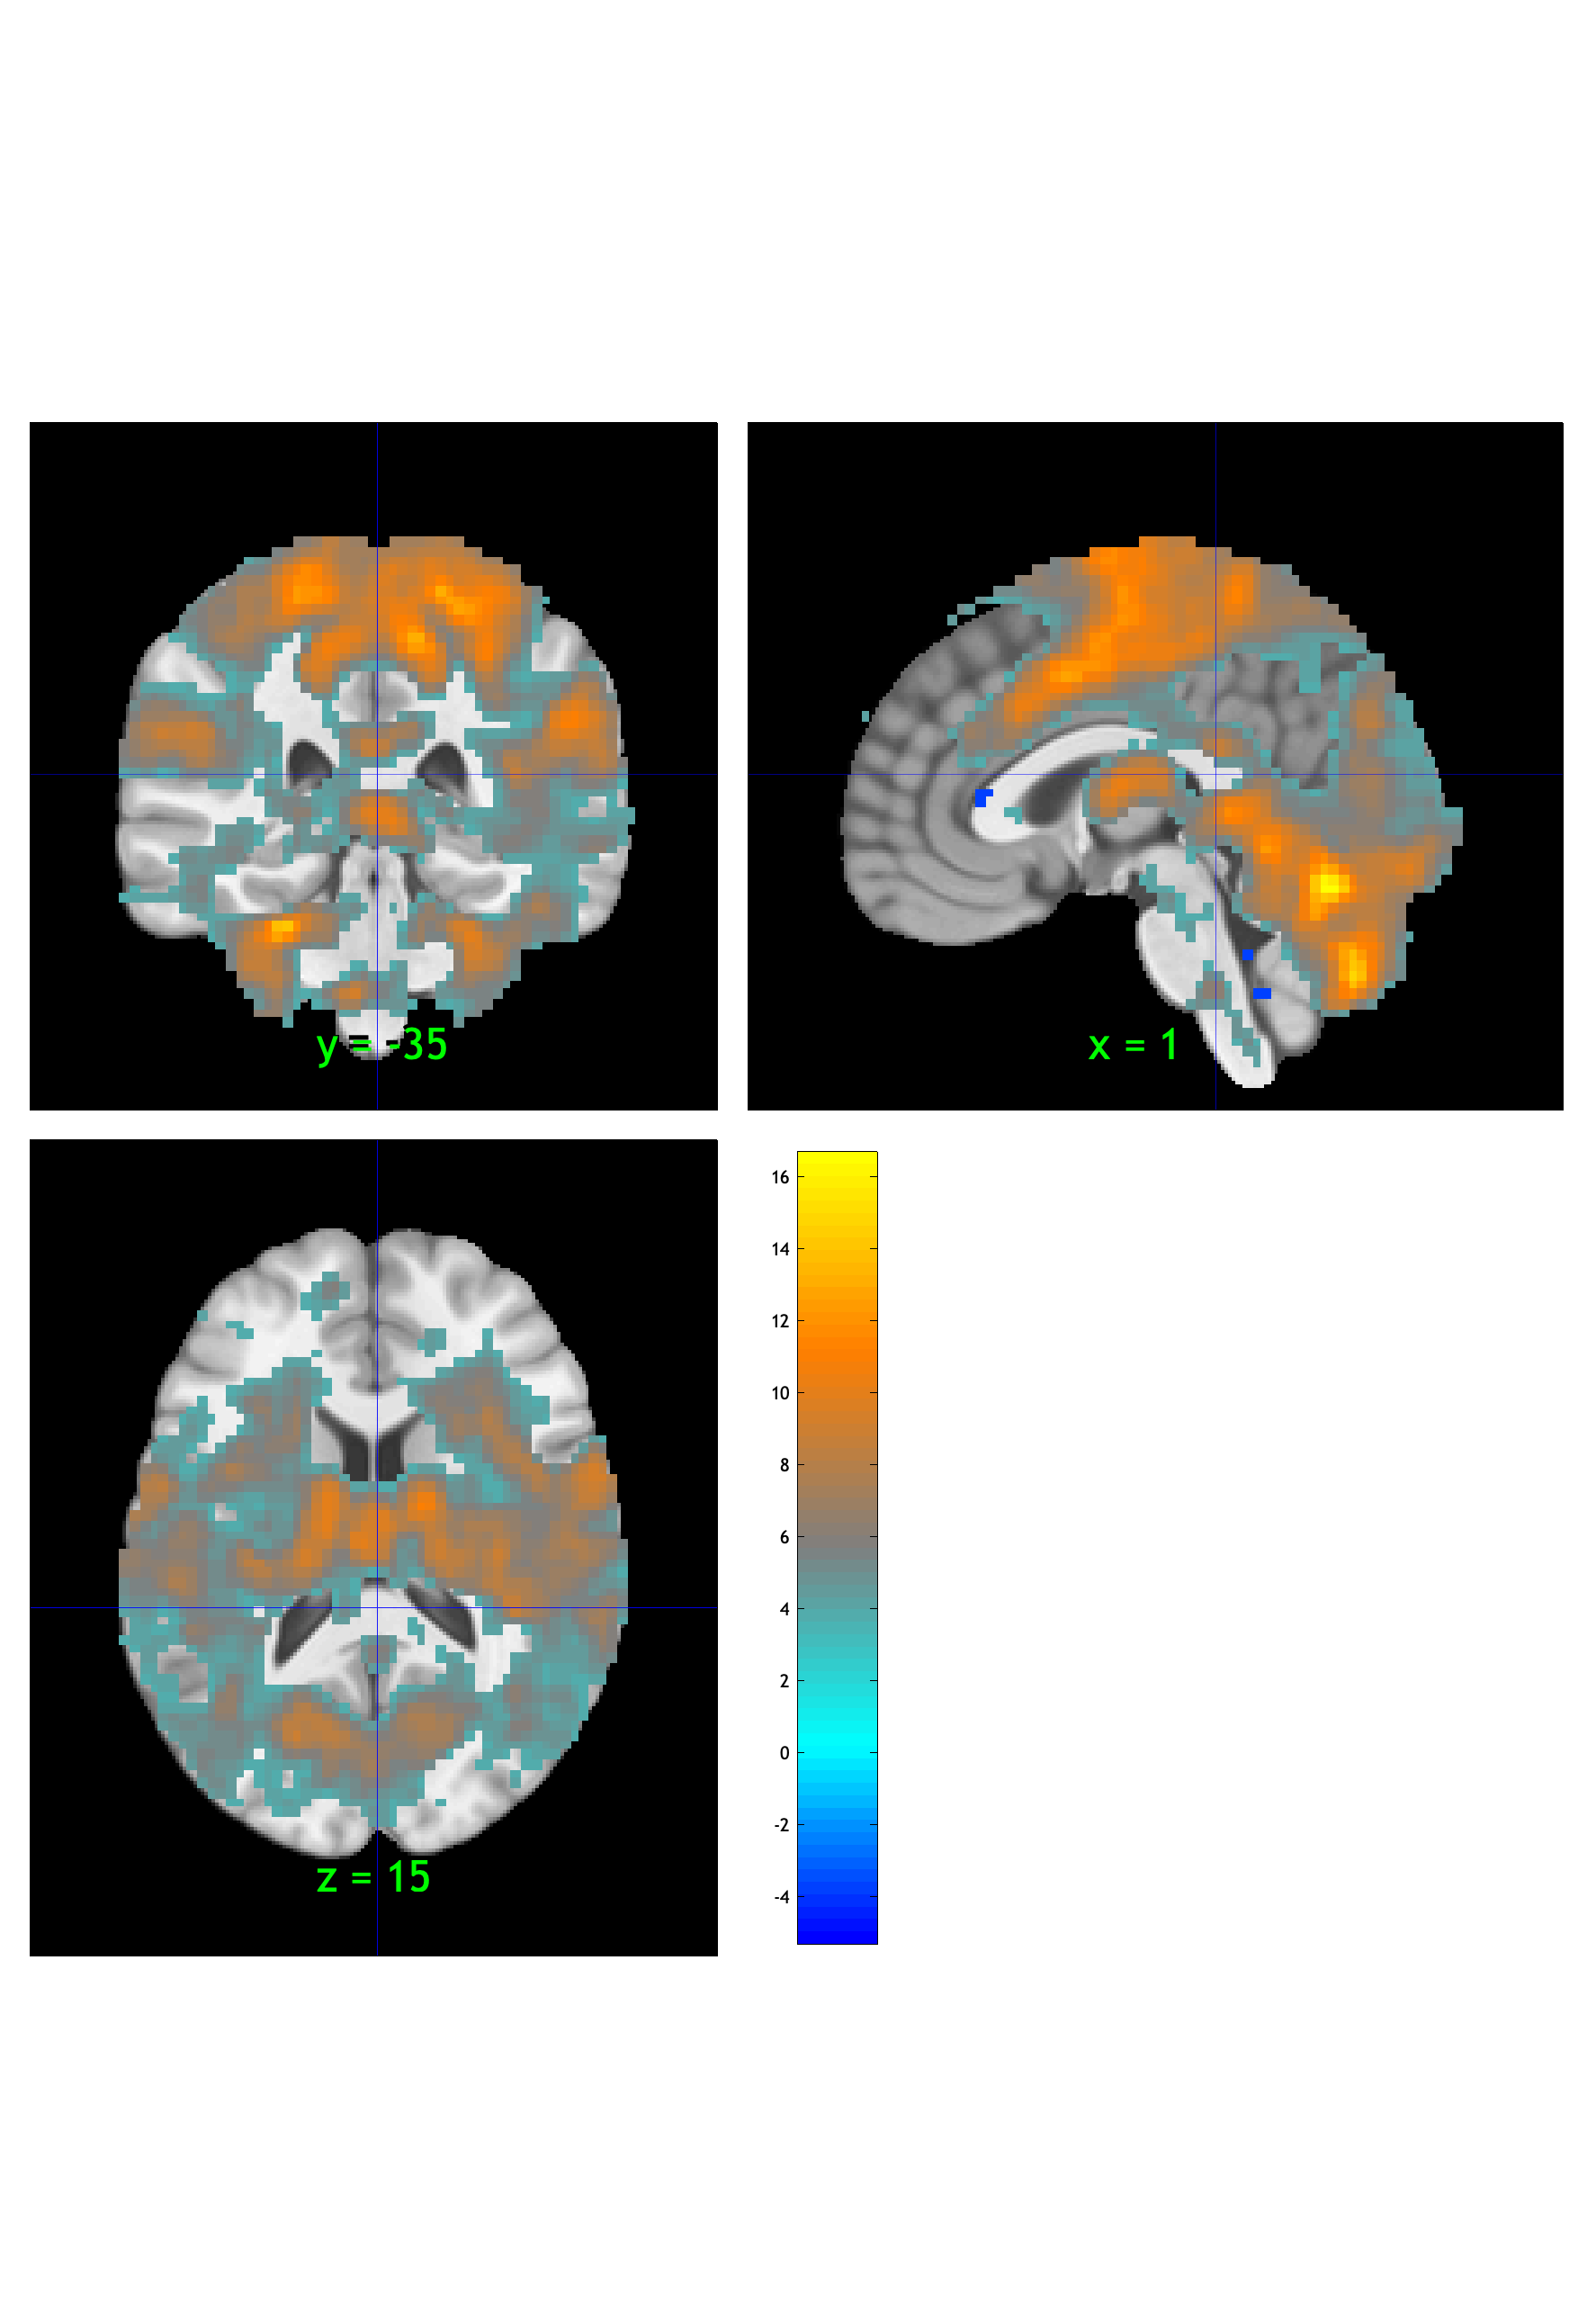

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:20:10 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


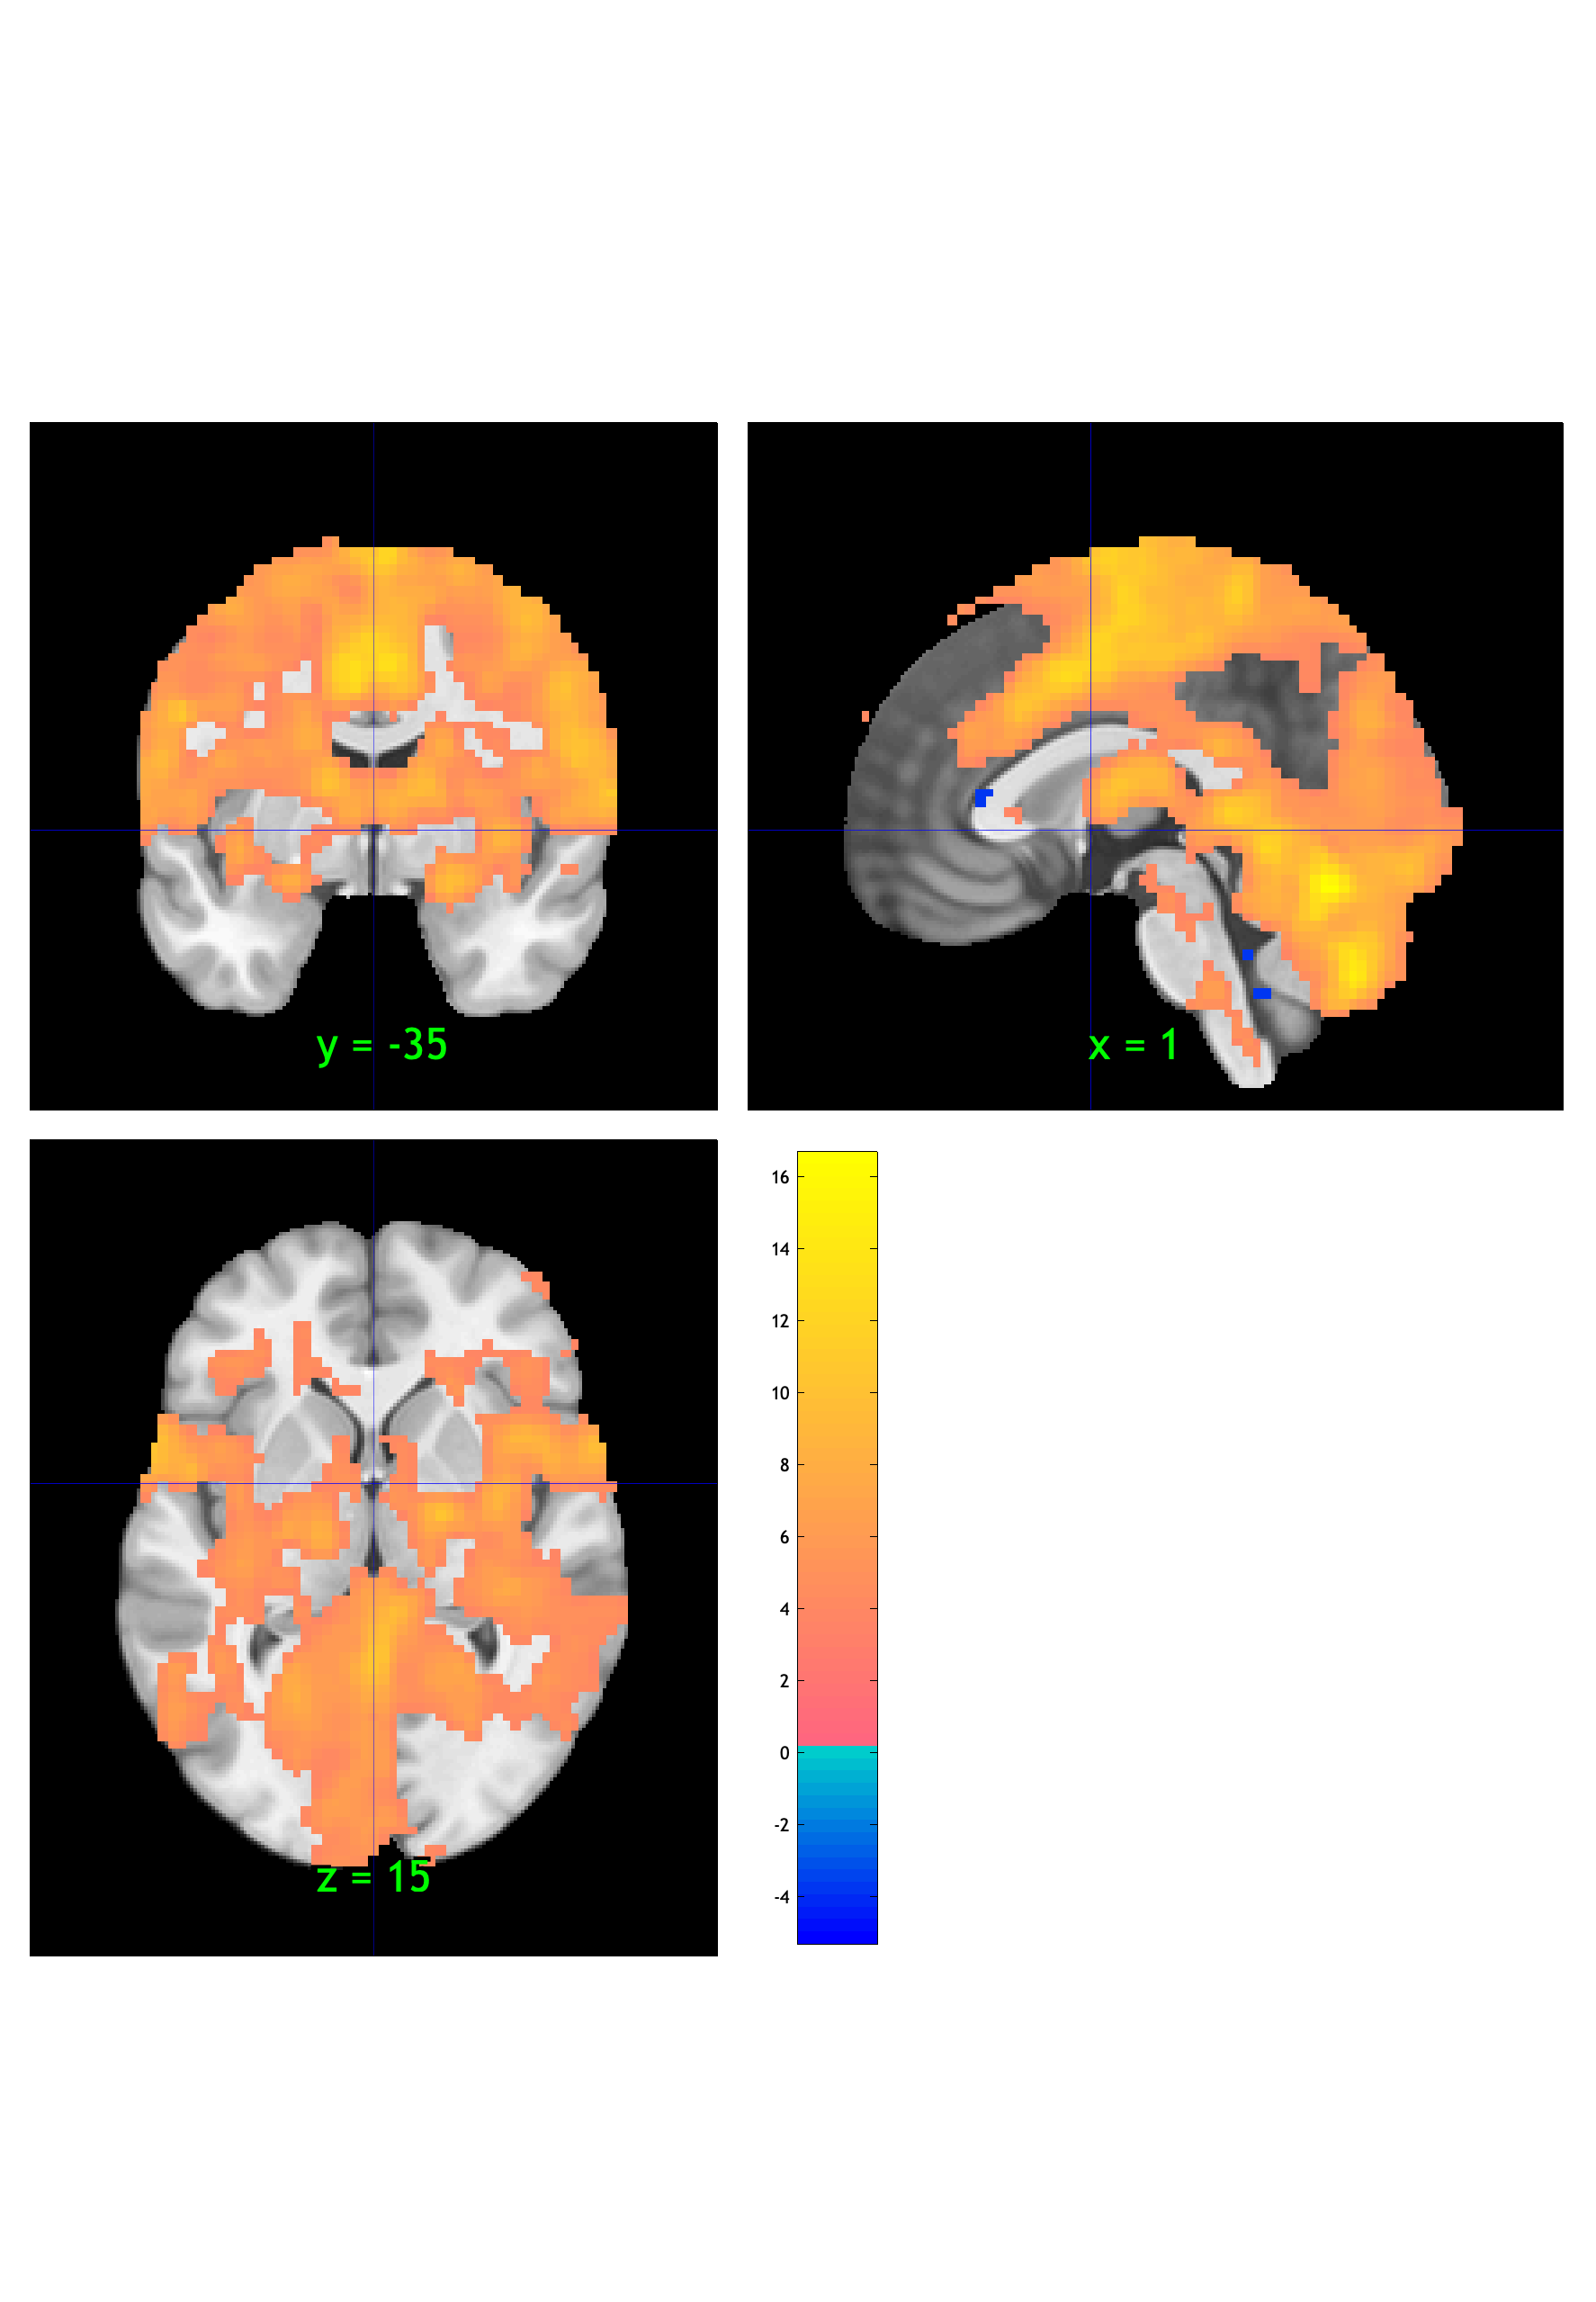

orthviews(fdr_t001);

drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig

fdr_t001 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 5.2691e-04
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 65
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


%write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');

create_figure('montage'); axis off;
montage(fdr_t001);

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 1289 voxels displayed, 51319 not displayed on these slices
sagittal montage: 1331 voxels displayed, 51277 not displayed on these slices
sagittal montage: 1262 voxels displayed, 51346 not displayed on these slices
axial montage: 8942 voxels displayed, 43666 not displayed on these slices
axial montage: 9927 voxels displayed, 42681 not displayed on these slices


drawnow, snapnow;

#### Pain > baseline :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low       testr_high       words_high    
    _________    _______________    __________    _________________

    -0.15923     {'judgment'   }     0.27972      {'motor'        }
    -0.15558     {'memory'     }     0.26058      {'movements'    }
    -0.14683     {'correct'    }     0.23725      {'sensorimotor' }
    -0.14126     {'pair'       }     0.23077      {'muscle'       }
    -0.13858     {'knowledge'  }     0.22761      {'finger'       }
    -0.13689     {'recognition'}     0.22494      {'hand'         }
    -0.13655     {'semantic'   }     0.22478      {'somatosensory'}
    -0.13357     {'sentence'   }     0.19473      {'tapping'      }
    -0.13214     {'person'     }     0.19406      {'sensory'      }
    -0.13199

% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

# `covariates "Cue effects (Zscore)"`

filtered_con_obj = fmri_data(filteredcon_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 28353708 bytes
Loading image number:    71
Elapsed time is 22.540099 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6767782  Bit rate: 22.69 bits


filtered_con_obj.X = filtered_pain_cueeffect.z_outcome_cue;
out = regress(filtered_con_obj)

Analysis: 
----------------------------------
Design matrix warnings:
----------------------------------
No intercept detected, adding intercept to last column of design matrix                                                     
Warning!!!  Some observations have high leverage values relative to others, regression may be unstable. abs(z(leverage)) > 3
Warning!!!  Too few variable names entered, less than size(X, 2). Names may be inaccurate.                                  
 
______________________________________________________
Running regression: 99837 voxels. Design:  71 obs,   2 regressors, intercept is last

Predicting exogenous variable(s) in dat.X using brain data as predictors, mass univariate
Running in OLS Mode
Model run in 0 minutes and 0.23 seconds

Creating beta and t images, thresholding t images
___________________________________________________

out = struct with fields:
             analysis_name: ''
          input_parameters: [1×1 struct]
      input_image_metadata: [1×1 struct]
                         X: [71×2 double]
            variable_names: {2×1 cell}
                         C: []
            contrast_names: {}
    contrast_summary_table: [0×0 table]
               diagnostics: [1×1 struct]
                  warnings: {1×4 cell}
                         b: [1×1 statistic_image]
                         t: [1×1 statistic_image]
                        df: [1×1 fmri_data]
                     sigma: [1×1 fmri_data]



m = mean(filtered_con_obj);
m.dat = sum(~isnan(filtered_con_obj.dat) & filtered_con_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:20:59 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 21.13%
Expected 3.55 outside 95% ellipsoid, found   9

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 5 images		Cases 16 29 37 44 69 
Uncorrected: 9 images		Cases 12 16 29 34 37 43 44 48 69 

Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 50.70%
Expected 3.55 outside 95% ellipsoid, found   3

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 3 images		Cases 12 20 33 

Mahalanobis (cov and corr, q<0.05 corrected):
  5 images 
                               Outlier_count    Percentage
             

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:21:27 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

wh_outlier_uncorr = 71×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


wh_outlier_corr = 71×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0



% Pain > baseline :: Plot diagnostics, before l2norm
drawnow; snapnow
[wh_outlier_uncorr, wh_outlier_corr] = plot(filtered_con_obj)

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;
con = filtered_con_obj;
disp(strcat("current length is ", num2str(size(filtered_con_obj.dat,2))))

current length is 71


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = filtered_con_obj.dat(:,~wh_outlier_corr);
con.image_names = filtered_con_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: [71×1 double]
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×66 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [66×21 char]
              fullpath: [71×136 char]
           files_exist: [71×1 logical]
            

con.fullpath = filtered_con_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: [71×1 double]
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×66 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [66×21 char]
              fullpath: [66×136 char]
           files_exist: [71×1 logical]
            

con.files_exist = filtered_con_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: [71×1 double]
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×66 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [66×21 char]
              fullpath: [66×136 char]
           files_exist: [66×1 logical]
            

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 5 participants, size is now 66



% plot diagnostics after l2norm
imgs2 = con.rescale('l2norm_images');

%
t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:21:31 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t05 = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.037811

Image   1
 36 contig. clusters, sizes   1 to 75189
Positive effect: 75174 voxels, min p-value: 0.00000000
Negative effect: 324 voxels, min p-value: 0.00000286


Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:21:33 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t05);

drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig

fdr_t05 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 0.0378
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 65
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


%write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

fdr_t001 = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000527

Image   1
 33 contig. clusters, sizes   1 to 52003
Positive effect: 52573 voxels, min p-value: 0.00000000
Negative effect:  35 voxels, min p-value: 0.00000286


Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:21:34 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t001);

drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig

fdr_t001 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 5.2691e-04
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 65
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


%write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');

create_figure('montage'); axis off;
montage(fdr_t001);

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 1289 voxels displayed, 51319 not displayed on these slices
sagittal montage: 1331 voxels displayed, 51277 not displayed on these slices
sagittal montage: 1262 voxels displayed, 51346 not displayed on these slices
axial montage: 8942 voxels displayed, 43666 not displayed on these slices
axial montage: 9927 voxels displayed, 42681 not displayed on these slices


drawnow, snapnow;

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low       testr_high       words_high    
    _________    _______________    __________    _________________

    -0.15923     {'judgment'   }     0.27972      {'motor'        }
    -0.15558     {'memory'     }     0.26058      {'movements'    }
    -0.14683     {'correct'    }     0.23725      {'sensorimotor' }
    -0.14126     {'pair'       }     0.23077      {'muscle'       }
    -0.13858     {'knowledge'  }     0.22761      {'finger'       }
    -0.13689     {'recognition'}     0.22494      {'hand'         }
    -0.13655     {'semantic'   }     0.22478      {'somatosensory'}
    -0.13357     {'sentence'   }     0.19473      {'tapping'      }
    -0.13214     {'person'     }     0.19406      {'sensory'      }
    -0.13199

# cue vs. stim effects (raw)

filtered_con_obj = fmri_data(filteredcon_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 28353708 bytes
Loading image number:    71
Elapsed time is 31.140673 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6767782  Bit rate: 22.69 bits


filtered_con_obj.X = filtered_pain_cueeffect.cuestim_raw_outcome;
out.b = regress(filtered_con_obj);

Analysis: 
----------------------------------
Design matrix warnings:
----------------------------------
No intercept detected, adding intercept to last column of design matrix                                                     
Warning!!!  Some observations have high leverage values relative to others, regression may be unstable. abs(z(leverage)) > 3
Warning!!!  Too few variable names entered, less than size(X, 2). Names may be inaccurate.                                  
 
______________________________________________________
Running regression: 99837 voxels. Design:  71 obs,   2 regressors, intercept is last

Predicting exogenous variable(s) in dat.X using brain data as predictors, mass univariate
Running in OLS Mode
Model run in 0 minutes and 0.67 seconds

Creating beta and t images, thresholding t images
___________________________________________________


m = mean(out.b);

Error using sum
Invalid data type. First argument must be numeric or logical.

Error in mean (line 127)
        y = sum(x, dim, flag) ./ mysize(x,dim);

m.dat = sum(~isnan(out.b.dat) & out.b.dat ~= 0, 2);
orthviews(m, 'trans') % display

% Pain > baseline :: Plot diagnostics, before l2norm
drawnow; snapnow
[wh_outlier_uncorr, wh_outlier_corr] = plot(out.b )
set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;
con = out.b ;
disp(strcat("current length is ", num2str(size(out.b.dat,2))))
%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = out.b.dat(:,~wh_outlier_corr);
con.image_names = out.b.image_names(~wh_outlier_corr,:)
con.fullpath = out.b.fullpath(~wh_outlier_corr,:)
con.files_exist = out.b.files_exist(~wh_outlier_corr,:)
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

% plot diagnostics after l2norm
imgs2 = con.rescale('l2norm_images');

%
t = ttest(imgs2);
orthviews(t);
drawnow, snapnow;

fdr_t05 = threshold(t, .05, 'fdr');
orthviews(fdr_t05);
drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig
%write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

fdr_t001 = threshold(t, .001, 'fdr');
orthviews(fdr_t001);
drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig
%write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');

create_figure('montage'); axis off;
montage(fdr_t001);
drawnow, snapnow;

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');



# covariate "cue stim effect ratio (Z score)

filtered_con_obj = fmri_data(filteredcon_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 28353708 bytes
Loading image number:    71
Elapsed time is 26.366445 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6767782  Bit rate: 22.69 bits


filtered_con_obj.X = filtered_pain_cueeffect.cuestim_z_outcome;
out = regress(filtered_con_obj)

Analysis: 
----------------------------------
Design matrix warnings:
----------------------------------
No intercept detected, adding intercept to last column of design matrix                                                     
Warning!!!  Some observations have high leverage values relative to others, regression may be unstable. abs(z(leverage)) > 3
Warning!!!  Too few variable names entered, less than size(X, 2). Names may be inaccurate.                                  
 
______________________________________________________
Running regression: 99837 voxels. Design:  71 obs,   2 regressors, intercept is last

Predicting exogenous variable(s) in dat.X using brain data as predictors, mass univariate
Running in OLS Mode
Model run in 0 minutes and 0.20 seconds

Creating beta and t images, thresholding t images
___________________________________________________

out = struct with fields:
             analysis_name: ''
          input_parameters: [1×1 struct]
      input_image_metadata: [1×1 struct]
                         X: [71×2 double]
            variable_names: {2×1 cell}
                         C: []
            contrast_names: {}
    contrast_summary_table: [0×0 table]
               diagnostics: [1×1 struct]
                  warnings: {1×4 cell}
                         b: [1×1 statistic_image]
                         t: [1×1 statistic_image]
                        df: [1×1 fmri_data]
                     sigma: [1×1 fmri_data]



m = mean(filtered_con_obj);
m.dat = sum(~isnan(filtered_con_obj.dat) & filtered_con_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:23:40 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 21.13%
Expected 3.55 outside 95% ellipsoid, found   9

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 5 images		Cases 16 29 37 44 69 
Uncorrected: 9 images		Cases 12 16 29 34 37 43 44 48 69 

Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 50.70%
Expected 3.55 outside 95% ellipsoid, found   3

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 3 images		Cases 12 20 33 

Mahalanobis (cov and corr, q<0.05 corrected):
  5 images 
                               Outlier_count    Percentage
             

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:24:07 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

wh_outlier_uncorr = 71×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


wh_outlier_corr = 71×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0



% Pain > baseline :: Plot diagnostics, before l2norm
drawnow; snapnow
[wh_outlier_uncorr, wh_outlier_corr] = plot(filtered_con_obj)

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;
con = filtered_con_obj;
disp(strcat("current length is ", num2str(size(filtered_con_obj.dat,2))))

current length is 71


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = filtered_con_obj.dat(:,~wh_outlier_corr);
con.image_names = filtered_con_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: [71×1 double]
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×66 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [66×21 char]
              fullpath: [71×136 char]
           files_exist: [71×1 logical]
            

con.fullpath = filtered_con_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: [71×1 double]
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×66 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [66×21 char]
              fullpath: [66×136 char]
           files_exist: [71×1 logical]
            

con.files_exist = filtered_con_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: [71×1 double]
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×66 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [66×21 char]
              fullpath: [66×136 char]
           files_exist: [66×1 logical]
            

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 5 participants, size is now 66



% plot diagnostics after l2norm
imgs2 = con.rescale('l2norm_images');

%
t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:24:11 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t05 = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.037811

Image   1
 36 contig. clusters, sizes   1 to 75189
Positive effect: 75174 voxels, min p-value: 0.00000000
Negative effect: 324 voxels, min p-value: 0.00000286


Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:24:12 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t05);

drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig

fdr_t05 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 0.0378
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 65
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


%write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

fdr_t001 = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000527

Image   1
 33 contig. clusters, sizes   1 to 52003
Positive effect: 52573 voxels, min p-value: 0.00000000
Negative effect:  35 voxels, min p-value: 0.00000286


Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:24:14 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t001);

drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig

fdr_t001 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 5.2691e-04
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 65
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


%write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');

create_figure('montage'); axis off;
montage(fdr_t001);

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 1289 voxels displayed, 51319 not displayed on these slices
sagittal montage: 1331 voxels displayed, 51277 not displayed on these slices
sagittal montage: 1262 voxels displayed, 51346 not displayed on these slices
axial montage: 8942 voxels displayed, 43666 not displayed on these slices
axial montage: 9927 voxels displayed, 42681 not displayed on these slices


drawnow, snapnow;

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low       testr_high       words_high    
    _________    _______________    __________    _________________

    -0.15923     {'judgment'   }     0.27972      {'motor'        }
    -0.15558     {'memory'     }     0.26058      {'movements'    }
    -0.14683     {'correct'    }     0.23725      {'sensorimotor' }
    -0.14126     {'pair'       }     0.23077      {'muscle'       }
    -0.13858     {'knowledge'  }     0.22761      {'finger'       }
    -0.13689     {'recognition'}     0.22494      {'hand'         }
    -0.13655     {'semantic'   }     0.22478      {'somatosensory'}
    -0.13357     {'sentence'   }     0.19473      {'tapping'      }
    -0.13214     {'person'     }     0.19406      {'sensory'      }
    -0.13199



% Phil tripartite marker
[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii.gz
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii.gz
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii.gz
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii.gz
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii.gz
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii.gz
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii.gz
/Use

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0080	-1.3385	0.1850	0.0000	
Cog Wholebrain	0.0057	1.3515	0.1808	0.0000	
Emo Wholebrain	0.0025	0.4492	0.6547	0.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T          P       Cohens_d
    ___________________    __________    _________    _______    _______    ________

    {'Pain Wholebrain'}    -0.0080255    0.0059974    -1.3382    0.18512     -0.1577
    {'Cog Wholebrain' }     0.0057277    0.0042358     1.3522     0.1806     0.15936
    {'Emo Wholebrain' }      0.002466    0.0055019    0.44821    0.65537    0.052822



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {72×3 cell}
        text_han: {72×3 cell}
       point_han: {72×3 cell}
    star_handles: [12.0010 13.0010 14.0006]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Warnin


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T          P       Cohens_d
    ___________________    __________    _________    _______    _______    ________

    {'Pain Wholebrain'}    -0.0082589    0.0058087    -1.4218    0.15946    -0.16756
    {'Cog Wholebrain' }     0.0043465    0.0039402     1.1031     0.2737        0.13
    {'Emo Wholebrain' }     0.0039084    0.0054372    0.71883     0.4746    0.084715



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {72×3 cell}
        text_han: {72×3 cell}
       point_han: {72×3 cell}
    star_handles: [15.0006 16.0002 17.0002]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')





# covariate: cue stim effect ratio (Z score) regularized

filtered_con_obj = fmri_data(filteredcon_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 28353708 bytes
Loading image number:    71
Elapsed time is 21.264193 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6767782  Bit rate: 22.69 bits


Analysis: 
----------------------------------
Design matrix warnings:
----------------------------------
No intercept detected, adding intercept to last column of design matrix                                                     
Warning!!!  Some observations have high leverage values relative to others, regression may be unstable. abs(z(leverage)) > 3
Warning!!!  Too few variable names entered, less than size(X, 2). Names may be inaccurate.                                  
 
______________________________________________________
Running regression: 99837 voxels. Design:  71 obs,   2 regressors, intercept is last

Predicting exogenous variable(s) in dat.X using brain data as predictors, mass univariate
Running in OLS Mode
Model run in 0 minutes and 0.29 seconds

Creating beta and t images, thresholding t images
___________________________________________________

out = struct with fields:
             analysis_name: ''
          input_parameters: [1×1 struct]
      input_image_metadata: [1×1 struct]
                         X: [71×2 double]
            variable_names: {2×1 cell}
                         C: []
            contrast_names: {}
    contrast_summary_table: [0×0 table]
               diagnostics: [1×1 struct]
                  warnings: {1×4 cell}
                         b: [1×1 statistic_image]
                         t: [1×1 statistic_image]
                        df: [1×1 fmri_data]
                     sigma: [1×1 fmri_data]


Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:25:23 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 21.13%
Expected 3.55 outside 95% ellipsoid, found   9

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 5 images		Cases 16 29 37 44 69 
Uncorrected: 9 images		Cases 12 16 29 34 37 43 44 48 69 

Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 50.70%
Expected 3.55 outside 95% ellipsoid, found   3

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 3 images		Cases 12 20 33 

Mahalanobis (cov and corr, q<0.05 corrected):
  5 images 
                               Outlier_count    Percentage
             

wh_outlier_uncorr = 71×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


wh_outlier_corr = 71×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


filtered_con_obj.X = filtered_pain_cueeffect.cuestim_z_outcome_reg;
out = regress(filtered_con_obj)


m = mean(out);
m.dat = sum(~isnan(filtered_con_obj.dat) & filtered_con_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

% Pain > baseline :: Plot diagnostics, before l2norm
drawnow; snapnow
[wh_outlier_uncorr, wh_outlier_corr] = plot(filtered_con_obj)
set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;
con = filtered_con_obj;
disp(strcat("current length is ", num2str(size(filtered_con_obj.dat,2))))

current length is 71


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = filtered_con_obj.dat(:,~wh_outlier_corr);
con.image_names = filtered_con_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: [71×1 double]
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×66 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [66×21 char]
              fullpath: [71×136 char]
           files_exist: [71×1 logical]
            

con.fullpath = filtered_con_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: [71×1 double]
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×66 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [66×21 char]
              fullpath: [66×136 char]
           files_exist: [71×1 logical]
            

con.files_exist = filtered_con_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: [71×1 double]
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×66 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [66×21 char]
              fullpath: [66×136 char]
           files_exist: [66×1 logical]
            

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 5 participants, size is now 66



% plot diagnostics after l2norm
imgs2 = con.rescale('l2norm_images');

%
t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:25:58 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t05 = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.037811

Image   1
 36 contig. clusters, sizes   1 to 75189
Positive effect: 75174 voxels, min p-value: 0.00000000
Negative effect: 324 voxels, min p-value: 0.00000286


Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:25:59 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t05);

drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig

fdr_t05 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 0.0378
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 65
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


%write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

fdr_t001 = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000527

Image   1
 33 contig. clusters, sizes   1 to 52003
Positive effect: 52573 voxels, min p-value: 0.00000000
Negative effect:  35 voxels, min p-value: 0.00000286


Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:26:01 - 11/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t001);

drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig

fdr_t001 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 5.2691e-04
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 65
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


%write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');

create_figure('montage'); axis off;
montage(fdr_t001);

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 1289 voxels displayed, 51319 not displayed on these slices
sagittal montage: 1331 voxels displayed, 51277 not displayed on these slices
sagittal montage: 1262 voxels displayed, 51346 not displayed on these slices
axial montage: 8942 voxels displayed, 43666 not displayed on these slices
axial montage: 9927 voxels displayed, 42681 not displayed on these slices


drawnow, snapnow;

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low       testr_high       words_high    
    _________    _______________    __________    _________________

    -0.15923     {'judgment'   }     0.27972      {'motor'        }
    -0.15558     {'memory'     }     0.26058      {'movements'    }
    -0.14683     {'correct'    }     0.23725      {'sensorimotor' }
    -0.14126     {'pair'       }     0.23077      {'muscle'       }
    -0.13858     {'knowledge'  }     0.22761      {'finger'       }
    -0.13689     {'recognition'}     0.22494      {'hand'         }
    -0.13655     {'semantic'   }     0.22478      {'somatosensory'}
    -0.13357     {'sentence'   }     0.19473      {'tapping'      }
    -0.13214     {'person'     }     0.19406      {'sensory'      }
    -0.13199



% Phil tripartite marker
[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii.gz
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii.gz
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii.gz
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii.gz
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii.gz
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii.gz
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii.gz
/Use

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0080	-1.3385	0.1850	0.0000	
Cog Wholebrain	0.0057	1.3515	0.1808	0.0000	
Emo Wholebrain	0.0025	0.4492	0.6547	0.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T          P       Cohens_d
    ___________________    __________    _________    _______    _______    ________

    {'Pain Wholebrain'}    -0.0080255    0.0059974    -1.3382    0.18512     -0.1577
    {'Cog Wholebrain' }     0.0057277    0.0042358     1.3522     0.1806     0.15936
    {'Emo Wholebrain' }      0.002466    0.0055019    0.44821    0.65537    0.052822



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {72×3 cell}
        text_han: {72×3 cell}
       point_han: {72×3 cell}
    star_handles: [11.0012 12.0011 13.0011]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Warnin


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T          P       Cohens_d
    ___________________    __________    _________    _______    _______    ________

    {'Pain Wholebrain'}    -0.0082589    0.0058087    -1.4218    0.15946    -0.16756
    {'Cog Wholebrain' }     0.0043465    0.0039402     1.1031     0.2737        0.13
    {'Emo Wholebrain' }     0.0039084    0.0054372    0.71883     0.4746    0.084715



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {72×3 cell}
        text_han: {72×3 cell}
       point_han: {72×3 cell}
    star_handles: [14.0007 15.0007 16.0004]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')



### cue stim z outcome

%plot_cov(filteredcon_files, 'cuestim_z_outcome_reg')

Error using s06_multiplereg_cov-outcomerating>plot_cov
Too many input arguments.

### cue stim regularized


%plot_cov('cuestim_z_outcome_reg')


function plot_cov(covariate_name)
% covariate_name = 'cuestim_z_outcome';
filtered_con_obj = fmri_data(filteredcon_files);
filtered_con_obj.X = filtered_pain_cueeffect.(covariate_name);

out = regress(filtered_con_obj)

m = mean(out);
m.dat = sum(~isnan(out.dat) & out.dat ~= 0, 2);
orthviews(m, 'trans') % display

% Pain > baseline :: Plot diagnostics, before l2norm
drawnow; snapnow
[wh_outlier_uncorr, wh_outlier_corr] = plot(out)
set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;
con = out;
disp(strcat("current length is ", num2str(size(filtered_con_obj.dat,2))))
%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = filtered_con_obj.dat(:,~wh_outlier_corr);
con.image_names = filtered_con_obj.image_names(~wh_outlier_corr,:)
con.fullpath = filtered_con_obj.fullpath(~wh_outlier_corr,:)
con.files_exist = filtered_con_obj.files_exist(~wh_outlier_corr,:)
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

% plot diagnostics after l2norm
imgs2 = con.rescale('l2norm_images');

%
t = ttest(imgs2);
orthviews(t);
drawnow, snapnow;

fdr_t05 = threshold(t, .05, 'fdr');
orthviews(fdr_t05);
drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig
%write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

fdr_t001 = threshold(t, .001, 'fdr');
orthviews(fdr_t001);
drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig
%write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');

create_figure('montage'); axis off;
montage(fdr_t001);
drawnow, snapnow;

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');


% Phil tripartite marker
[obj, names] = load_image_set('pain_cog_emo');
bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');
axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)
set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)
set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

end